%% Coupled transport aircraft sizing and longitudinal CG
% Standalone MATLAB script. All inputs are specified below.
% Fixed installed thrust and fixed wing area define the design point at each mass.
% Fuel mass is unchanged; crew and payload are added once.
% Standalone: component weights, fuel layout and five loading cases.
clear; clc;
folder = fileparts(mfilename('fullpath'));
if isempty(folder), folder = pwd; end
centreTankVolume_m3 = 32.00;       % select 32.00 or 28.85
fuelDensity_kgm3 = 800;
targetCombinedFuelCG_m = 28.2572345;  % m aft of nose
% Script-defined inputs take precedence over the parameter record.
AR = 10;
W0 = 267609;           % Initial take-off mass [kg]
e_oswald = 0.70;
CD0 = 0.0186;
M_cruise = 0.82;
L_runway = 3000;       % m
abs_ceil_ft = 42000;
V_climb = 150;         % m/s
gamma_req = 0.024;
g          = 9.81;
ft2m       = 0.3048;
sigma_to   = 1.0;      % density ratio for sea level
K_R        = 1.0;      % runway correction factor
Sa         = 305;      % air distance safety margin [m]
CLmax_L    = 2.55;     % landing CL_max (slide 23)
CLmax_TO   = 2.33;     % take-off CL_max
CL_LOF     = 0.8*CLmax_TO;
NE         = 2;        % number of engines
alpha_to   = 1.0;      % take-off weight ratio
taxiMassRatio = 0.99;
fuelFraction_TO = (0.35296 - (1 - taxiMassRatio)) / taxiMassRatio;
alpha_cr = (0.97 * 0.985) / taxiMassRatio;  % cruise weight ratio (0.97*0.985)
alpha_ceil = alpha_cr*0.712;   % weight ratio at absolute ceiling
beta_cr    = 0.23;     % thrust lapse, cruise (slide 12)
beta_30k   = 0.30;     % thrust lapse, 30,000 ft line
beta_40k   = 0.20;     % thrust lapse, 40,000 ft line
beta_ceil  = 0.20;     % thrust lapse, absolute ceiling
installedThrust_N = 2 * 392.5e3;  % Total installed take-off thrust [N], both engines
S_ref_out = 400.17;%422.199;              % Fixed wing reference area [m^2]
b_out = sqrt(AR*S_ref_out);
areaScale = S_ref_out/422.199;

K_induced  = 1/(pi*AR*e_oswald);   % induced drag factor

%% ------------------------------------------------------------------------
%% 2. WING LOADING GRID AND LIMITS
%% ------------------------------------------------------------------------
N_WS = 8000;
WS   = linspace(500, 9000, N_WS);  % wing loading [N/m^2]

ALD_max          = 0.60*L_runway;
WS_landing_limit = (ALD_max - Sa)*sigma_to*CLmax_L/(0.51*K_R);   % check vs slide

%% ------------------------------------------------------------------------
%% 3. CONSTRAINT CURVES (T/W against W/S)
%% ------------------------------------------------------------------------
% Take-off (Raymer take-off parameter)
TOP_req    = L_runway/(0.297 - 0.019*NE);
TW_takeoff = (WS/(sigma_to*CL_LOF*TOP_req))/alpha_to;

% OEI climb (constant in W/S)
TW_climb2     = (gamma_req + 2*sqrt(CD0*K_induced)) / 0.5;
TW_climb2_vec = TW_climb2*ones(size(WS));

% AEO Go-Around (constant in W/S)
TW_climb3     = (gamma_req + 2*sqrt(0.11*K_induced));
TW_climb3_vec = TW_climb3*ones(size(WS));

% Absolute ceiling: V_x evaluated at ceiling density (updated in the solver below)
h_ceil_m            = abs_ceil_ft*ft2m;
[~, ~, ~, rho_ceil] = atmosisa(h_ceil_m);

% Cruise lines
TW_30k = cruiseTW(WS, 30000, beta_30k, alpha_cr, M_cruise, CD0, K_induced, ft2m);
TW_37k = cruiseTW(WS, 37000, beta_cr,  alpha_cr, M_cruise, CD0, K_induced, ft2m);
TW_40k = cruiseTW(WS, 40000, beta_40k, alpha_cr, M_cruise, CD0, K_induced, ft2m);

% Climb lines
TW_c10_3000 = climbTW(WS, 1000,  3000, V_climb, 0.85,    alpha_cr, CD0, K_induced, ft2m);
TW_c10_1500 = climbTW(WS, 10000, 1500, V_climb, 0.85,    alpha_cr, CD0, K_induced, ft2m);
[~, a_cruise, ~, ~] = atmosisa(37000*ft2m);
V_c37k      = M_cruise*a_cruise;                    % estimated TAS at 37,000 ft
TW_c37k     = climbTW(WS, 37000, 500, V_c37k, beta_cr, alpha_cr, CD0, K_induced, ft2m);
b_max = 65;

% Calculate separately at EVERY wing loading.
V_ceil  = sqrt(2*alpha_ceil*WS/rho_ceil) .* (K_induced/CD0)^(1/4);
q_ceil  = 0.5*rho_ceil .* V_ceil.^2;
TW_ceil = (alpha_ceil/beta_ceil) .* (q_ceil.*CD0./(alpha_ceil*WS) + K_induced.*(alpha_ceil*WS)./q_ceil);

% Envelope: required T/W is the maximum of all constraints
% Include AEO go-around, which was omitted previously.
TW_env = max([TW_takeoff;
              TW_ceil;
              TW_climb2_vec;
              TW_climb3_vec;
              TW_30k;
              TW_37k;
              TW_40k;
              TW_c10_3000;
              TW_c10_1500;
              TW_c37k], [], 1);

%% Iterate mass with fixed geometry and installed thrust
KG2LB = 2.20462;
LB2T = 1000*KG2LB;
massTolerance_kg = 0.1;
maxIterations = 100;
for iteration = 1:maxIterations
    ws = W0*g/S_ref_out;
    TW_design = installedThrust_N/(W0*g);

    % ------------------------------------------------------------------------
    %  VARIABLES - input!!!!
    x_ac_w    = 28.5;     % Original wing station, m from nose
    x_root_ht = 51.3785;  % HT root leading edge, m aft of nose
    x_root_vt = 53.03;    % VT root leading edge, m aft of nose
    % ------------------------------------------------------------------------

    % --- Crew / payload --- [confirmed]
    n_pilots     = 3;                 % Flight crew on all four loading cases
    n_cabin_crew = 5;                 % Cabin crew on passenger cases
    N_c = n_pilots + n_cabin_crew;    % Staffed passenger configuration
    N_seat_E    = 90;                 % Economy seats [confirmed]
    N_seat_PE   = 36;                 % Premium economy seats [confirmed]
    N_seat_B    = 24;                 % Business seats [confirmed]
    N_pax       = N_seat_E + N_seat_PE + N_seat_B;   % Passengers (150) [confirmed]
    N_p         = N_pax + N_c;        % Total persons onboard (crew + passengers) [confirmed]

    % --- Geometry: wing --- [confirmed]
    Bw       = 3.281*b_out;                 % Wing span (ft) [variable]
    Sw       = 3.281^2*S_ref_out;           % Reference wing area (ft^2) [variable]
    Scsw     = 3.281^2*47.44*areaScale;     % Area of wing mounted control surfaces (ft^2) [variable]
    lambda   = 0.255;                      % Wing taper ratio [confirmed]
    Lambda_w = 32.14;                       % Wing quarter chord sweep (deg) [confirmed]
    tc_root  = 0.14;                        % (t/c)_root, wing root thickness to chord ratio [confirmed]

    % --- Geometry: horizontal tail --- [confirmed]
    S_ref_A_m2 = S_ref_out;                 % [confirmed]
    c_root_A_m = 2*S_ref_out/(b_out*(1+lambda));        % Wing root chord [m]
    MAC_A_m    = (2/3) * c_root_A_m * (1 + lambda + lambda^2) / (1 + lambda);
    S_e        = 23.75/ft2m^2;              % Elevator area (ft^2) [variable]
    AR_h       = 4;
    tr_h       = 0.4;
    Lambda_ht  = 36;                        % Quarter-chord sweep [deg]
    Ht_Hv      = 0;                         % Fuselage-mounted HT
    [S_ht_m2, x_ac_ht] = sizeTail(S_ref_A_m2*MAC_A_m, x_root_ht, x_ac_w, ...
        AR_h, tr_h, Lambda_ht, 0.5);
    tail_arm_A_m = x_ac_ht - x_ac_w;
    L_ht    = 3.281*tail_arm_A_m;
    S_ht    = 3.281^2*S_ht_m2;
    B_t     = sqrt(AR_h*S_ht);              % Horizontal tailplane span (ft) [confirmed]
    c_root_h = 2*S_ht / (B_t*(1 + tr_h));
    c_tip_h  = tr_h * c_root_h;
    MAC_h    = (2/3) * c_root_h * (1 + tr_h + tr_h^2) / (1 + tr_h);

    % --- Geometry: vertical tail --- [confirmed]
    span_A_m  = b_out;
    AR_v      = 1.7;
    tr_v      = 0.35;
    Lambda_vt = 40;                         % Quarter-chord sweep [deg]
    [S_vt_m2, x_ac_vt] = sizeTail(0.09*S_ref_A_m2*span_A_m, x_root_vt, x_ac_w, ...
        AR_v, tr_v, Lambda_vt, 1);
    tail_arm_vt_m = x_ac_vt - x_ac_w;
    L_vt    = 3.281*tail_arm_vt_m;
    S_vt    = 3.281^2*S_vt_m2;
    tc_root_v = 0.11;                       % (t/c)_root_v [variable]
    b_v       = sqrt(AR_v*S_vt);            % Vertical tail height [ft]
    c_root_v  = 2*S_vt / (b_v*(1 + tr_v));
    c_tip_v   = tr_v * c_root_v;
    MAC_v     = (2/3) * c_root_v * (1 + tr_v + tr_v^2) / (1 + tr_v);

    % --- Geometry: fuselage / nacelle --- [confirmed]
    D              = 3.281*5.8047;          % Maximum fuselage diameter (ft) [confirmed]
    x_tail_tip_m   = 62.988;                % Tail-tip station from nose [m]
    tail_taper_m   = 11.6095;               % Length of tapered afterbody [m]
    x_tail_start_m = x_tail_tip_m - tail_taper_m;
    D_tail_start_m = 5.8047;                % Diameter at start of taper [m]
    D_tail_tip_m   = 1.08;                  % Diameter at tail tip [m]
    x95_m = x_tail_start_m + 0.95*tail_taper_m;   % 95% along tapered afterbody
    D_local = @(x) interp1([x_tail_start_m, x95_m, x_tail_tip_m], ...
                           [D_tail_start_m, 1.161, D_tail_tip_m], x, 'linear');
    F_w = 3.281*D_local(x_root_ht);         % Local diameter at centre-mounted HT root [ft]
    assert(isfinite(F_w) && isfinite(D_local(x_root_vt)), 'Tail roots outside afterbody.');
    L_f               = 3.281*x_tail_tip_m; % Total fuselage length (ft) [confirmed]
    x_tailcap_joint_m = 0.517;              % Tail-cap structural joint location (m) [confirmed]
    x_radome_joint_m  = 1.795;              % Radome structural joint location (m) [confirmed]
    L      = 3.281*(L_f/3.281 - x_tailcap_joint_m - x_radome_joint_m);  % Fuselage structural length (ft)
    S_f    = 3.281^2*1006.1;                % Fuselage wetted area (ft^2) [confirmed]
    N_Lt   = 6.56 / 0.3048;                 % Nacelle length (ft) [confirmed]
    N_w    = 3.34 / 0.3048;                 % Nacelle width (ft) [confirmed]
    S_n    = 60.0 / 0.3048^2;               % Nacelle wetted area (ft^2) [confirmed]
    V_pr   = 3.281^3*1048.2;                % Volume of pressurized sections (ft^3) [confirmed]

    % --- Propulsion --- [unconfirmed]
    N_en    = 2;                            % Number of engines [confirmed]
    x_engine = x_ac_w/0.3048 - 0.5*N_Lt;    % Existing engine CG estimate [ft]
    y_pylon  = mean([11.37, 11.87]) / 0.3048;
    L_ec     = 2*(x_engine + y_pylon);      % Engine controls routing distance (ft) [unconfirmed]

    % --- Fuel system --- [confirmed]
    W_dg    = KG2LB*W0;                     % Design gross weight (lb) [confirmed]
    W_fuel  = W_dg * fuelFraction_TO;       % Fuel weight (lb)
    V_t     = (W_fuel/KG2LB/fuelDensity_kgm3) * 264.172; % Fuel volume (gal)
    V_i     = V_t;                          % Integral fuel tank volume (gal) [confirmed]
    V_p     = 0;                            % Self sealing tank volume (gal) [confirmed]
    N_t     = 3;                            % Total number of fuel tanks [confirmed]

    % --- Weights --- [confirmed]
    W_l      = W_dg - W_fuel*0.7;           % Landing design gross weight (lb), 70% of loaded fuel consumed
    W_en     = KG2LB*7265;                  % Engine weight (lb) [confirmed]
    W_APU    = 762;                         % Uninstalled APU weight (lb) [confirmed]
    W_c      = KG2LB*(40000 + N_seat_B*35 + N_seat_PE*28 + N_seat_E*23);  % Max cargo + pax bags (lb) [confirmed]
    TW0      = TW_design;                   % Thrust-to-weight ratio T/W0 [variable]
    W_uav    = 0.02*(W_dg*(0.32 + 0.66*W_dg^(-0.13)*AR^0.30*TW0^0.06*(W_dg/Sw)^(-0.05)*M_cruise^0.05)*1.0);  % Uninstalled avionics [confirmed]
    W_seat_E  = 35*KG2LB;                   % Weight of single economy seat (lb)
    W_seat_PE = 80*KG2LB;                   % Weight of single premium economy seat (lb)
    W_seat_B  = 175*KG2LB;                  % Weight of single business class seat (lb)
    N_LD3    = 62;
    W_ULD_lb = N_LD3 * 74 * KG2LB;

    % --- Load factors --- [confirmed]
    N_z    = 1.5*2.5;                       % Ultimate load factor = 1.5 x limit load factor
    N_gear = 3;                             % Ratio of avg total main gear load on landing to max landing weight
    N_l    = 1.5*N_gear;                    % Ultimate landing gear load factor

    % --- Landing gear ---
    L_m     = 39.3701*5;                    % Existing Raymer mass estimate input (in)
    L_n     = 39.3701*5;                    % Nose landing gear length (in) [guess]
    N_mw    = 12;                           % Number of main wheels [confirmed]
    N_nw    = 2;                            % Number of nose wheels [confirmed]
    N_mss   = 2;                            % Number of main gear shock struts
    V_stall_TO_mps = 65.48;                 % Recorded take-off stall speed [m/s]
    V_stall_L_mps  = 49.82;                 % Landing stall speed [m/s]

    % --- Controls / systems ---
    N_f   = 7;                              % Number of functions performed by controls [confirmed]
    N_m   = 0;                              % Number of mechanical functions performed by controls [confirmed]
    S_cs  = (20.63+26.39+23.75+20.39)/ft2m^2;   % Total control surface area (ft^2) [unconfirmed]
    R_kva = 400;                            % System electrical rating (kVA) [confirmed]
    L_a   = L_ec;                           % Electrical routing distance (ft) [unconfirmed]
    N_gen = 4;                              % Number of generators [confirmed]

    % --- Empirical K factors --- [confirmed]
    K_buf  = 5.68;    % very long ranges
    K_door = 1.18;    % 1.18 = 1 + 0.06*3
    K_lav  = 1.11;    % long range
    K_Lg   = 1.0;
    K_mp   = 1.0;
    K_ng   = 1.017;   % pylon mounted nacelle
    K_np   = 1.0;
    K_r    = 1.0;
    K_tp   = 1.0;
    K_uht  = 1.0;
    K_p    = 1.0;
    K_tr   = 1.18;    % jet with thrust reversers

    % --- Derived quantities from the nomenclature ---
    K_ws  = 0.75*((1 + 2*lambda)/(1 + lambda))*Bw*tand(Lambda_w)/L;  % Wing sweep factor
    K_y   = 0.3*L_ht;                       % Pitching radius of gyration (ft)
    K_z   = L_vt;                           % Yaw radius of gyration (ft)
    I_y   = W_dg*K_y^2;                     % Pitching moment of inertia (lb ft^2)
    W_enc = 2.331*K_p*K_tr*W_en^0.901;      % Weight of engine and contents (lb)

    % --- Material factors (from Raymer) --- [confirmed]
    MF_w  = 0.78;   % wing
    MF_tp = 0.75;   % tail planes
    MF_F  = 0.85;   % fuselage / nacelle
    MF_lg = 0.88;   % landing gear

    % ------------------------------------------------------------------------
    %  WEIGHT EQUATIONS
    % ------------------------------------------------------------------------
    % Wing
    W_w = (0.0051*(W_dg*N_z)^0.557*Sw^0.649*AR^0.5*(1 + lambda)^0.1*Scsw^0.1) ...
          ./(cosd(Lambda_w)*tc_root^0.4);
    W_w = MF_w*W_w;

    % Horizontal tail
    W_ht = (0.0379*K_uht*W_dg^0.639*N_z^0.1*S_ht^0.75*K_y^0.704*AR_h^0.166 ...
           *(1 + S_e/S_ht)^0.1) ...
           ./((1 + F_w/B_t)^0.25*L_ht*cosd(Lambda_ht));
    W_ht = MF_tp*W_ht;

    % Vertical tail
    W_vt = (0.0026*(1 + Ht_Hv)^0.225*W_dg^0.556*N_z^0.536*S_vt^0.5*K_z^0.875*AR_v^0.35) ...
           ./(L_vt^0.5*cosd(Lambda_vt)*tc_root_v^0.5);
    W_vt = MF_tp*W_vt;

    % Fuselage
    W_fus = 0.3280*K_door*K_Lg*(W_dg*N_z)^0.5*L^0.25*S_f^0.302*(1 + K_ws)^0.04*(L/D)^0.1;
    W_fus = MF_F*W_fus;

    % Main landing gear
    W_main_landing_gear = 0.0106*K_mp*W_l^0.888*N_l^0.25*L_m^0.4*N_mw^0.321*(V_stall_L_mps/0.514444)^0.1/N_mss^0.5;
    W_main_landing_gear = MF_lg*W_main_landing_gear;

    % Nose landing gear
    W_nose_landing_gear = 0.032*K_np*W_l^0.646*N_l^0.2*L_n^0.5*N_nw^0.45;
    W_nose_landing_gear = MF_lg*W_nose_landing_gear;

    % Nacelle
    W_nacelle = 0.6724*K_ng*N_Lt^0.1*N_w^0.294*N_z^0.119*W_enc^0.611*N_en^0.984*S_n^0.224;
    W_nacelle = MF_F*W_nacelle;

    % Engines
    W_engines = N_en*W_en;

    % Engine controls
    W_ec = 5*N_en + 0.8*L_ec;

    % Engine (pneumatic) starter
    W_es = 49.19*(N_en*W_en/1e3)^0.541;

    % Fuel system
    W_fuel_system = 2.405*V_t^0.606*N_t^0.5*(1 + V_p/V_t)/(1 + V_i/V_t);

    % Flight controls
    W_flight_controls = 145.9*N_f^0.554*S_cs^0.2*(I_y*1e-6)^0.07/(1 + N_m/N_f);

    % Installed APU
    W_APUinst = 2.2*W_APU;

    % Instruments
    W_instruments = 4.509*K_r*K_tp*N_c^0.541*N_en*(L_f + Bw)^0.5;

    % Hydraulic system
    W_hydraulic = 0.2673*N_f*(L_f + Bw)^0.937;

    % Electrical system
    W_electrical = 7.291*R_kva^0.782*L_a^0.346*N_gen^0.1;

    % Avionics
    W_avionics = 1.73*W_uav^0.983;

    % Furnishings
    W_furnishings = 0.0577*N_c^0.1*W_c^0.393*S_f^0.75 ...
        + N_seat_E*W_seat_E + N_seat_PE*W_seat_PE + N_seat_B*W_seat_B ...
        + K_lav*N_p^1.33 + K_buf*N_p^1.12 + W_ULD_lb;

    % Air-conditioning
    W_ac = 62.36*N_p^0.25*(V_pr*1e-3)^0.604*W_uav^0.1;

    % Anti-icing system
    W_anti_icing = 0.002*W_dg;

    % Handling gear (civilian)
    W_hg = 3.0e-4*W_dg;

    % ------------------------------------------------------------------------
    %  SUMMARY
    % ------------------------------------------------------------------------
    names   = {'Wing','Horizontal tail','Vertical tail','Fuselage','Main landing gear', ...
               'Nose landing gear','Nacelle','Engines','Engine controls','Engine starter','Fuel system', ...
               'Flight controls','Installed APU','Instruments','Hydraulics','Electrical', ...
               'Avionics','Furnishings','Air-conditioning','Anti-icing','Handling gear'};
    weights = [W_w W_ht W_vt W_fus W_main_landing_gear W_nose_landing_gear W_nacelle W_engines W_ec W_es W_fuel_system W_flight_controls W_APUinst ...
               W_instruments W_hydraulic W_electrical W_avionics W_furnishings W_ac W_anti_icing W_hg];

    payloadCrew_lb = [N_pax*84*KG2LB, W_c, N_c*84*KG2LB];
    cg_weights     = [weights, W_fuel, payloadCrew_lb];
    builtMass_kg   = sum(cg_weights)/KG2LB;
    validateattributes(builtMass_kg, {'numeric'}, {'scalar','real','finite','positive'});
    residual_kg = builtMass_kg - W0;
    if abs(residual_kg) <= massTolerance_kg
        break
    end
    if iteration == maxIterations
        error('MTOW failed to close after %d iterations. Residual %+.3f kg.', iteration, residual_kg);
    end
    W0 = builtMass_kg;
end

WS_span_min = W0*g*AR/b_max^2;
fprintf('\nMTOW %.3f kg, component sum including load %.3f kg, residual %+.4f kg (%d iterations).\n', ...
    W0, builtMass_kg, residual_kg, iteration);


MTOW 247588.000 kg, component sum including load 247587.914 kg, residual -0.0862 kg (18 iterations).


TW_required = interp1(WS, TW_env, ws, 'linear');
V_x_out     = sqrt(2*alpha_ceil*ws/rho_ceil)*(K_induced/CD0)^(1/4);
if ~isfinite(TW_required)
    warning('Converged W/S lies outside the plotted performance grid.');
elseif TW_design < TW_required || ws > WS_landing_limit || b_out > b_max
    warning('Mass closed; the design violates a thrust, landing or span constraint.');
else
    fprintf('Converged point meets the modelled thrust, landing and span constraints.\n');
end

Converged point meets the modelled thrust, landing and span constraints.



% Print results
fprintf('\n=== 1. SIZING AND FUEL DESIGN POINT ===\n');


=== 1. SIZING AND FUEL DESIGN POINT ===


fprintf('Design W/S         = %.2f N/m^2\n', ws);

Design W/S         = 6069.52 N/m^2


fprintf('Selected T/W       = %.4f\n', TW_design);

Selected T/W       = 0.3232


fprintf('Minimum required TW= %.4f\n', TW_required);

Minimum required TW= 0.2895


fprintf('Wing area          = %.2f m^2\n', S_ref_out);

Wing area          = 400.17 m^2


fprintf('Wingspan           = %.2f m\n', b_out);

Wingspan           = 63.26 m


fprintf('Landing W/S limit  = %.2f N/m^2\n', WS_landing_limit);

Landing W/S limit  = 7475.00 N/m^2


weights_kg = weights/KG2LB;   % weight in kg
T = table(names', weights', weights_kg', 'VariableNames', {'Component','Weight_lb','weight_kg'});

% ------------------------------------------------------------------------
%  LOCATION OF WEIGHTS FOR CG
% ------------------------------------------------------------------------
% Raymer approximate group method: wing/tails at 40% MAC,
% fuselage at 40-50% length; 45% selected here.
L_f_m = L_f/3.281;
D_m   = D/3.281;
b_w_m = Bw/3.281;
S_w_m = Sw/3.281^2;
cr_w_m  = 2*S_w_m/(b_w_m*(1 + lambda));            % Trapezoidal wing assumption
MAC_w   = (2/3)*cr_w_m*(1 + lambda + lambda^2)/(1 + lambda);

lambda_ht_cg = tr_h;
lambda_vt_cg = tr_v;
b_ht_m  = B_t/3.281;
S_ht_m  = S_ht/3.281^2;
cr_ht_m = 2*S_ht_m/(b_ht_m*(1 + lambda_ht_cg));
MAC_ht  = (2/3)*cr_ht_m*(1 + lambda_ht_cg + lambda_ht_cg^2)/(1 + lambda_ht_cg);

S_vt_m  = S_vt/3.281^2;
b_vt_m  = sqrt(AR_v*S_vt_m);                       % Fin height (b^2 = AR*S)
cr_vt_m = 2*S_vt_m/(b_vt_m*(1 + lambda_vt_cg));
MAC_vt  = (2/3)*cr_vt_m*(1 + lambda_vt_cg + lambda_vt_cg^2)/(1 + lambda_vt_cg);

% Aerodynamic centres assumed at 25% MAC to locate MAC leading edges
x_LEMAC_w  = x_ac_w  - 0.25*MAC_w;
x_LEMAC_ht = x_ac_ht - 0.25*MAC_ht;
x_LEMAC_vt = x_ac_vt - 0.25*MAC_vt;

% Wing z position
wing_root_chord_m = 10.5439;
wing_tip_chord_m  = 2.4515;
wing_span_m       = 63.26;%4.9769;
% Wing-box placement includes the selected 1.5 m vertical offset; z positive down.
floor_top_z_m     = -0.2315;
floor_thickness_m = 0.05 * 5.5507;
wing_box_depth_m  = 0.14 * wing_root_chord_m;
z_w = floor_top_z_m + floor_thickness_m + 0.5*wing_box_depth_m + 1.5;

z_center  = @(x) -(x - x_tail_start_m)*tand(12);
z_ht_base = z_center(x_root_ht);                           % HT root at local centre [m]
z_vt_base = z_center(x_root_vt) - 0.5*D_local(x_root_vt);  % VT root at local crown [m]

x_engine_m = x_engine*0.3048;             % Installation station [guess]
z_engine_m = z_w + 0.5*N_w*0.3048;        % Installation station [guess]

x_cockpit   = 5;                                  % Flight deck station [guess]
x_cabin     = 25.753 + 8.75;                      % Combined cabin/crew station [guess]
x_equipment = 0.40*L_f_m;                         % Distributed systems station [guess]

% Component positions (m)
% Aircraft wings
c35  = 10.5439 + 0.35*(2.4515 - 10.5439);         % Local chord at 35% semispan [m]
xW_w = x_ac_w + (11.37096 - 12.87240)*tand(Lambda_w) + (0.43 - 0.25)*c35;
zW_w = z_w;

% Horizontal tail: 38% semispan, 42% local chord
c38_ht = cr_ht_m * (1 - 0.38*(1 - lambda_ht_cg));
xW_ht  = x_root_ht + 0.25*cr_ht_m + 0.38*(b_ht_m/2)*tand(Lambda_ht) + 0.17*c38_ht;
zW_ht  = z_ht_base;

% Vertical tail: trapezoidal centroid height, 40% MAC
h_vt  = b_vt_m*(1 + 2*lambda_vt_cg)/(3*(1 + lambda_vt_cg));
xW_vt = x_root_vt + 0.25*cr_vt_m + h_vt*tand(Lambda_vt) + 0.15*MAC_vt;
zW_vt = z_vt_base - h_vt;

% Fuselage
xW_fus = 0.45*L_f_m;   zW_fus = 0;

% Flight mass centroid of the retracted main gear.
fuelLayout = buildFuelLayout(centreTankVolume_m3,S_w_m,b_w_m,lambda,Lambda_w,x_ac_w);

Centre 28.85 m^3: x 23.000 to 30.882 m; xCG 26.425 m from nose.
Total 107.461 m^3 excluding surge; margin to 114.692 m^3 legacy target -7.231 m^3.
Centre 32.00 m^3: x 23.000 to 31.560 m; xCG 26.897 m from nose.
Total 110.611 m^3 excluding surge; margin to 114.692 m^3 legacy target -4.081 m^3.
Stowed gear 30.00% MAC at 28.853 m from nose; tank top 1.15 m below fuselage centre.
Check lower cargo floor, wing carry-through and gear retraction sweep in CAD.


gearMassStationMAC = fuelLayout.gearStationMAC;
xW_main_landing_gear = x_LEMAC_w + gearMassStationMAC*MAC_w;
zW_main_landing_gear = z_w;

% Nose landing gear (retracted)
xW_nose_landing_gear = 6;                        zW_nose_landing_gear = 0.35*D_m;

% Nacelle and engines
xW_nacelle = x_engine_m;  zW_nacelle = z_engine_m;
xW_engines = x_engine_m;  zW_engines = z_engine_m;

% Engine controls
xW_ec = (x_cockpit + x_engine_m)/2;  zW_ec = z_w/2;

% Engine starter
xW_es = x_engine_m;  zW_es = z_engine_m;

% Fuel system
xW_fuel_system = xW_w;
zW_fuel_system = z_w;

% Flight controls
iamstupid = (-0.2315 + D_m/2)/2;        % -0.2315 is the floor upper surface
xW_flight_controls = x_equipment;  zW_flight_controls = 0;

% Installed APU
xW_APUinst = x95_m - 1.82/2;  zW_APUinst = z_center(xW_APUinst);

% Instruments
xW_instruments = x_cockpit;  zW_instruments = iamstupid;

% Hydraulics
xW_hydraulic = x_equipment;  zW_hydraulic = iamstupid;

% Electrical
xW_electrical = x_equipment;  zW_electrical = iamstupid;

% Avionics
xW_avionics = x_equipment;  zW_avionics = 0;

% Air-conditioning
xW_ac = x_equipment;  zW_ac = iamstupid;

% Anti-icing
xW_anti_icing = xW_w;  zW_anti_icing = z_w;

% Fuel, passengers, cargo, crew
m_fuel_kg   = W_fuel / KG2LB;
optionIndex = find(abs([fuelLayout.centreOptions.capacity_m3]-centreTankVolume_m3)<1e-8,1);
assert(~isempty(optionIndex),'Selected centre tank volume was unavailable in the layout.');
centreOption = fuelLayout.centreOptions(optionIndex);
m_center_kg = centreOption.capacity_m3*fuelDensity_kgm3;
m_wings_kg = m_fuel_kg-m_center_kg;
assert(m_wings_kg>0,'The selected full centre tank exceeds the total mission fuel mass.');
wingFuelNeed_m3 = m_wings_kg/fuelDensity_kgm3;
wingFuelCapacity_m3 = sum(fuelLayout.wingCellVolume_m3);
assert(wingFuelNeed_m3<=wingFuelCapacity_m3, ...
    'Wing fuel needs %.3f m^3 but only %.3f m^3 fits.',wingFuelNeed_m3,wingFuelCapacity_m3);

x_center_tank = centreOption.xCG_m;
requiredWingFuelCG_m = (m_fuel_kg*targetCombinedFuelCG_m-m_center_kg*x_center_tank)/m_wings_kg;
xWingFuelMin_m = boundWingFuelCG(fuelLayout.wingCellX_m, ...
    fuelLayout.wingCellVolume_m3,wingFuelNeed_m3,'ascend');
xWingFuelMax_m = boundWingFuelCG(fuelLayout.wingCellX_m, ...
    fuelLayout.wingCellVolume_m3,wingFuelNeed_m3,'descend');
% Select the nearest geometric bound if the target exceeds the cell envelope.
% The bounds permit independent cell filling; real compartments need CAD checks.
xWingFuelCG_m = min(max(requiredWingFuelCG_m,xWingFuelMin_m),xWingFuelMax_m);
fuelTargetPass = abs(xWingFuelCG_m-requiredWingFuelCG_m)<1e-6;
xW_Fuel = (m_center_kg*x_center_tank+m_wings_kg*xWingFuelCG_m)/m_fuel_kg;
zW_Fuel = (m_center_kg*centreOption.zCG_m+m_wings_kg*z_w)/m_fuel_kg;
fprintf('Underfloor centre tank %.2f m^3, fuel CG %.3f m aft of nose.\n', ...
    centreOption.capacity_m3,x_center_tank);

Underfloor centre tank 32.00 m^3, fuel CG 26.897 m aft of nose.


fprintf('Mission fuel volume %.3f m^3; wing volume required %.3f of %.3f m^3.\n', ...
    m_fuel_kg/fuelDensity_kgm3,wingFuelNeed_m3,wingFuelCapacity_m3);

Mission fuel volume 107.213 m^3; wing volume required 75.213 of 78.611 m^3.


fprintf('Wing fuel CG required %.3f m; geometric range %.3f to %.3f m.\n', ...
    requiredWingFuelCG_m,xWingFuelMin_m,xWingFuelMax_m);

Wing fuel CG required 28.836 m; geometric range 28.574 to 29.207 m.


fprintf('Combined fuel CG %.3f m; target lies in geometric range = %d.\n', ...
    xW_Fuel,fuelTargetPass);

Combined fuel CG 28.257 m; target lies in geometric range = 1.


fprintf('Gear mass model uses %.3f m length; layout pivot to axle is %.3f m.\n', ...
    L_m/39.3701,fuelLayout.gearLength_m);

Gear mass model uses 5.000 m length; layout pivot to axle is 5.565 m.


x_cabin_start = 8.75;                            % m aft of nose
xW_Pass = x_cabin_start + 13.018816;
zW_Pass = -0.4565;                               % cabin z position

% Wing box and lower-deck row layout
wingbox_length = 11.86;
x_box_mid   = x_ac_w + 0.25*MAC_A_m;
x_box_front = x_box_mid - wingbox_length/2;
x_box_aft   = x_box_mid + wingbox_length/2;
n_rows_total = N_LD3/2;
n_rows_upper = 11;
n_lower      = n_rows_total - n_rows_upper;
row_pitch_m  = 1.53416;
[x_rows_forward, x_rows_aft] = arrangeLD3(x_cabin_start, L_f_m - 10.041, ...
    x_box_front, x_box_aft, row_pitch_m, n_lower);
n_rows_forward = numel(x_rows_forward);
n_rows_aft     = numel(x_rows_aft);
x_upper = x_cabin_start + 25.829 + 17.26/2;

%% ---- Luggage and ULDs: uniform row centroid (original layout) ----
xW_bag = (n_rows_upper*x_upper + sum(x_rows_forward) + sum(x_rows_aft))/n_rows_total;
zW_bag = (n_rows_upper*(-D_m/2 + 0.2315) + n_lower*(D_m/2 - 0.2315))/n_rows_total;

%% ---- 40 t cargo zoning ----
% ADJUSTABLE INPUTS
m_cargo_kg  = 40000;   % cargo mass [kg], excludes luggage and ULDs
V_LD3_m3    = 4.8;     % gross volume per LD3 position [m^3] (replace with spec value)
LD3_per_row = 2;
rho_fwd     = 200;     % ADJUSTABLE forward lower-deck density [kg/m^3]
eta_fwd     = 0.90;    % forward lower-deck efficiency
eta_up      = 0.85;    % upper-deck efficiency
eta_aft     = 0.85;    % aft lower-deck efficiency

% Effective zone volumes [m^3]
V_fwd_eff = n_rows_forward*LD3_per_row*V_LD3_m3*eta_fwd;
V_up_eff  = n_rows_upper  *LD3_per_row*V_LD3_m3*eta_up;
V_aft_eff = n_rows_aft    *LD3_per_row*V_LD3_m3*eta_aft;

% Forward mass from the input density
m_fwd = rho_fwd*V_fwd_eff;
assert(m_fwd <= m_cargo_kg, ...
    'Forward zone holds more than the cargo mass. Lower rho_fwd or the efficiency.');

% Rest of cargo (upper deck + aft lower deck) shares one calculated density
m_rest   = m_cargo_kg - m_fwd;
rho_rest = m_rest/(V_up_eff + V_aft_eff);
rho_up   = rho_rest;
rho_aft  = rho_rest;
m_up     = rho_up*V_up_eff;
m_aft    = rho_aft*V_aft_eff;
assert(abs(m_up + m_fwd + m_aft - m_cargo_kg) < 1e-6, 'Zone masses do not sum to cargo mass.');

% Zone centroids
x_cg_up  = x_upper;                 z_cg_up  = -D_m/2 + 0.2315;
x_cg_fwd = mean(x_rows_forward);    z_cg_fwd = D_m/2 - 0.2315;
x_cg_aft = mean(x_rows_aft);        z_cg_aft = D_m/2 - 0.2315;

% Centroid of the 40 t cargo only
x_cg_cargo = (m_up*x_cg_up + m_fwd*x_cg_fwd + m_aft*x_cg_aft)/m_cargo_kg;
z_cg_cargo = (m_up*z_cg_up + m_fwd*z_cg_fwd + m_aft*z_cg_aft)/m_cargo_kg;

% Combined "Cargo" CG entry: 40 t cargo + luggage (one CG line)
m_bags_kg = W_c/KG2LB - m_cargo_kg;               % luggage [kg]
xW_Cargo  = (m_cargo_kg*x_cg_cargo + m_bags_kg*xW_bag)/(W_c/KG2LB);
zW_Cargo  = (m_cargo_kg*z_cg_cargo + m_bags_kg*zW_bag)/(W_c/KG2LB);

% Handling gear and furnishings use the luggage/ULD centroid
xW_hg = xW_bag;   zW_hg = zW_bag;

xW_crew = (n_pilots*x_cockpit + n_cabin_crew*x_cabin)/N_c;  zW_crew = -0.4565;

x_cabin_mid    = x_cabin_start + 25.753/2;
xW_furnishings = ((W_furnishings - W_ULD_lb)*x_cabin_mid + W_ULD_lb*xW_bag)/W_furnishings;
zW_furnishings = 0;

% ------------------------------------------------------------------------
%  CG CALCULATION (listed loading case, gear retracted)
% ------------------------------------------------------------------------
cg_names = [names {'Fuel','Passengers','Cargo','Crew'}];

x_pos = [xW_w xW_ht xW_vt xW_fus xW_main_landing_gear xW_nose_landing_gear xW_nacelle xW_engines xW_ec xW_es xW_fuel_system xW_flight_controls ...
         xW_APUinst xW_instruments xW_hydraulic xW_electrical xW_avionics xW_furnishings xW_ac xW_anti_icing xW_hg ...
         xW_Fuel xW_Pass xW_Cargo xW_crew];
z_pos = [zW_w zW_ht zW_vt zW_fus zW_main_landing_gear zW_nose_landing_gear zW_nacelle zW_engines zW_ec zW_es zW_fuel_system zW_flight_controls ...
         zW_APUinst zW_instruments zW_hydraulic zW_electrical zW_avionics zW_furnishings zW_ac zW_anti_icing zW_hg ...
         zW_Fuel zW_Pass zW_Cargo zW_crew];

cg_mass_kg    = cg_weights(:)/KG2LB;
x_m           = x_pos(:);
z_m           = z_pos(:);
moment_x_kg_m = cg_mass_kg.*x_m;
moment_z_kg_m = cg_mass_kg.*z_m;

total_mass_kg = sum(cg_mass_kg);
x_CG = sum(moment_x_kg_m)/total_mass_kg;
z_CG = sum(moment_z_kg_m)/total_mass_kg;

CG_table = table(cg_names(:), cg_mass_kg, x_m, z_m, ...
    moment_x_kg_m, moment_z_kg_m, 'VariableNames', ...
    {'Component','Mass_kg','x_m','z_m','MassMomentX_kg_m','MassMomentZ_kg_m'});
total_row = table({'TOTAL / CG'}, total_mass_kg, x_CG, z_CG, ...
    sum(moment_x_kg_m), sum(moment_z_kg_m), ...
    'VariableNames', CG_table.Properties.VariableNames);
CG_table = [CG_table; total_row];
fprintf('\n=== 2. COMPONENT MASS AND FLIGHT CG (FULL LOAD) ===\n');


=== 2. COMPONENT MASS AND FLIGHT CG (FULL LOAD) ===


disp(CG_table);

          Component           Mass_kg       x_m        z_m      MassMomentX_kg_m    MassMomentZ_kg_m
    _____________________    __________    ______    _______    ________________    ________________

    {'Wing'             }         21008    28.945     2.2841       6.0808e+05              47985    
    {'Horizontal tail'  }        2180.1    56.909          0       1.2406e+05                  0    
    {'Vertical tail'    }        2098.7    60.475    -7.6043       1.2692e+05             -15959    
    {'Fuselage'         }         17084    28.345          0       4.8425e+05                  0    
    {'Main landing gear'}         12284    28.853     2.2841       3.5443e+05              28057    
    {'Nose landing gear'}        1405.1         6     2.0316           8430.4           


fprintf('\n=== 3. CARGO DISTRIBUTION (40 t NET FREIGHT) ===\n');


=== 3. CARGO DISTRIBUTION (40 t NET FREIGHT) ===


cargoZone = ["Lower deck before wing"; "Lower deck after wing"; "Upper deck"];
cargoRows = [n_rows_forward; n_rows_aft; n_rows_upper];
cargoBoxes = LD3_per_row*cargoRows;
cargoDensity = [rho_fwd; rho_aft; rho_up];
cargoEfficiency = [eta_fwd; eta_aft; eta_up];
cargoEffectiveVolume = [V_fwd_eff; V_aft_eff; V_up_eff];
cargoMass = [m_fwd; m_aft; m_up];
cargoX = [x_cg_fwd; x_cg_aft; x_cg_up];
cargoZ = [z_cg_fwd; z_cg_aft; z_cg_up];
cargoTable = table(cargoZone,cargoRows,cargoBoxes,cargoDensity,cargoEfficiency, ...
    cargoEffectiveVolume,cargoMass,cargoX,cargoZ, ...
    'VariableNames',{'Zone','Rows','LD3_Boxes','Density_kg_m3','PackingEfficiency', ...
    'EffectiveVolume_m3','NetCargo_kg','ZoneCG_x_m','ZoneCG_z_m'});
disp(cargoTable);

              Zone              Rows    LD3_Boxes    Density_kg_m3    PackingEfficiency    EffectiveVolume_m3    NetCargo_kg    ZoneCG_x_m    ZoneCG_z_m
    ________________________    ____    _________    _____________    _________________    __________________    ___________    __________    __________

    "Lower deck before wing"     10        20              200               0.9                  86.4              17280         16.544        2.6709  
    "Lower deck after wing"      10        20           132.59              0.85                  81.6              10819         44.572        2.6709  
    "Upper deck"                 11        22           132.59              0.85 

fprintf('Wing-box limits, x from nose: %.3f to %.3f m.\n',x_box_front,x_box_aft);

Wing-box limits, x from nose: 24.337 to 36.197 m.


fprintf('Lower LD3 row centres from nose (m), before wing:');

Lower LD3 row centres from nose (m), before wing:

fprintf(' %.3f',x_rows_forward);

 9.640 11.174 12.708 14.242 15.777 17.311 18.845 20.379 21.913 23.447

fprintf('\nLower LD3 row centres from nose (m), after wing:');


Lower LD3 row centres from nose (m), after wing:

fprintf(' %.3f',x_rows_aft);

 37.668 39.203 40.737 42.271 43.805 45.339 46.873 48.408 49.942 51.476

fprintf('\nUpper cargo bay from nose: %.3f to %.3f m; centroid %.3f m.\n', ...
    x_upper-17.26/2,x_upper+17.26/2,x_upper);


Upper cargo bay from nose: 34.579 to 51.839 m; centroid 43.209 m.


fprintf('Total: %d LD3s, %.0f kg net freight; cargo CG x = %.3f m, z = %.3f m.\n', ...
    sum(cargoBoxes),sum(cargoMass),x_cg_cargo,z_cg_cargo);

Total: 62 LD3s, 40000 kg net freight; cargo CG x = 32.058 m, z = 1.082 m.



% Mass closure: listed loading case vs design gross weight
W_case_lb   = sum(cg_weights);
closure_pct = 100*(W_case_lb - W_dg)/W_dg;
fprintf('Loading case: %.7f t vs design gross weight %.2f t (difference %.2f %%)\n', ...
    W_case_lb/LB2T, W_dg/LB2T, closure_pct);

Loading case: 247.5879143 t vs design gross weight 247.59 t (difference -0.00 %)



% ------------------------------------------------------------------------
%  DESIGN CHECKS
% ------------------------------------------------------------------------
% Provisional limits from the reference report, confirm for this aircraft.
tipback_required_deg = 10.7;
nose_fraction_min    = 0.05;
SM_min               = 0.04;
SM_max               = 0.25;

% Ground geometry (m): x aft from nose, z down from fuselage centre.
x_mlg_attach_m     = 36.48;  % Reference attachment station aft of nose [m]
y_mlg_attach_min_m = 3.76;   % Minimum absolute lateral offset per attachment [m]
h_CG_ground        = 5.0;    % Given deployed aircraft CG height above ground [m]

% Provisional ground layout, all x coordinates aft of nose [m].
% The stowed layout does not establish a kinematic link to these values.
x_nose_contact  = 6.00;    % Nose-wheel ground reaction
x_main_reaction = 31.10;   % Effective main-wheel ground reaction
x_main_pivot    = 31.10;   % Assume tipping pivot at the main reaction
x_main_deployed = 31.10;   % Assume deployed main-gear mass CG at the reaction
z_main_deployed = NaN;     % Replace with CAD-derived vertical mass CG
x_nose_deployed = 6.00;    % Assume no longitudinal nose-gear mass shift
z_nose_deployed = NaN;     % Replace with CAD-derived vertical mass CG

% Ground CG: replace retracted gear moments with deployed moments
x_CG_ground = (sum(moment_x_kg_m) ...
    + W_main_landing_gear/KG2LB*(x_main_deployed - xW_main_landing_gear) ...
    + W_nose_landing_gear/KG2LB*(x_nose_deployed - xW_nose_landing_gear))/total_mass_kg;
z_CG_ground = (sum(moment_z_kg_m) ...
    + W_main_landing_gear/KG2LB*(z_main_deployed - zW_main_landing_gear) ...
    + W_nose_landing_gear/KG2LB*(z_nose_deployed - zW_nose_landing_gear))/total_mass_kg;
z_ground = z_CG_ground + h_CG_ground;

nose_fraction = NaN;
cg_angle_deg  = NaN;
nose_status   = "NOT EVALUATED - fill deployed geometry";
angle_status  = "NOT EVALUATED - fill deployed geometry";

if all(isfinite([x_CG_ground x_nose_contact x_main_reaction]))
    if x_main_reaction > x_nose_contact
        nose_fraction = (x_main_reaction - x_CG_ground)/(x_main_reaction - x_nose_contact);
        nose_status = "FAIL";
        if nose_fraction > nose_fraction_min && nose_fraction < 1
            nose_status = "PASS";
        end
    else
        nose_status = "INVALID - main reaction must be aft of nose contact";
    end
end

if all(isfinite([x_CG_ground h_CG_ground x_main_pivot]))
    if h_CG_ground > 0
        cg_angle_deg = atand((x_main_pivot - x_CG_ground)/h_CG_ground);
        angle_status = "FAIL";
        if cg_angle_deg > tipback_required_deg
            angle_status = "PASS";
        end
    else
        angle_status = "INVALID - CG must be above ground";
    end
end

% Stability model (preliminary aerodynamic inputs at one condition)
CLaw_check       = 7;         % Wing lift-curve slope (per rad)
CLawm0_check     = 6.69889;   % Zero-Mach wing lift-curve slope (per rad)
CLah_check       = 4;         % Horizontal-tail lift-curve slope (per rad)
eta_check        = 0.9;
Kf_check         = 1.2;       % Fuselage factor, review if wing station changes
power_on_margin  = 0.02;      % Assumed power-on static-margin reduction

hh_check = abs(z_ht_base - z_w);          % Vertical separation of wing and tail (m)
lh_check = x_ac_ht - x_ac_w;              % Tail arm (m)
KA_check      = 1/AR - 1/(1 + AR^1.7);
Klambda_check = (10 - 3*lambda)/7;
Kh_check      = (1 - abs(hh_check/b_w_m))/(2*lh_check/b_w_m)^(1/3);
de_da_check   = 4.44*(KA_check*Klambda_check*Kh_check*sqrt(cosd(Lambda_w)))^1.19 ...
              *(CLaw_check/CLawm0_check);
CMaf_check    = Kf_check*L_f_m*D_m^2/(MAC_w*S_w_m);
tail_slope_check = eta_check*CLah_check*(1 - de_da_check)*(S_ht_m/S_w_m);
xnp_check     = (CLaw_check*x_ac_w - CMaf_check*MAC_w ...
              + tail_slope_check*x_ac_ht)/(CLaw_check + tail_slope_check);

SM_off    = (xnp_check - x_CG)/MAC_w;
SM_on     = SM_off - power_on_margin;
SM_values = [SM_off; SM_on];
SM_status = ["NOT EVALUATED"; "NOT EVALUATED"];
for k = 1:2
    if isreal(SM_values(k)) && isfinite(SM_values(k))
        SM_status(k) = "FAIL";
        if SM_values(k) >= SM_min && SM_values(k) < SM_max
            SM_status(k) = "PASS";
        end
    end
end

Check       = ["Vertical CG angle (ground)"; "Nose gear static load"; ...
               "Static margin, power off"; "Static margin, power on"];
Value       = [cg_angle_deg; 100*nose_fraction; 100*SM_off; 100*SM_on];
Units       = ["deg"; "% weight"; "% MAC"; "% MAC"];
Requirement = ["> " + string(tipback_required_deg); ...
               "> " + string(100*nose_fraction_min) + " and < 100"; ...
               string(100*SM_min) + " to " + string(100*SM_max); ...
               string(100*SM_min) + " to " + string(100*SM_max)];
Status      = [angle_status; nose_status; SM_status];
Check_table = table(Check, Value, Units, Requirement, Status);
%% ------------------------------------------------------------------------
%  Four-point centre of gravity loading envelope (gear retracted)
%  Method: bare OEW (components minus ULDs, plus all crew) + case-specific loads.
% ------------------------------------------------------------------------
mULD  = W_ULD_lb/KG2LB;                    % ULD mass [kg], carried inside furnishings
mxULD = mULD*xW_bag;

% 1. Operating empty weight (OEW)
M_oew = sum(cg_mass_kg(1:21)) - mULD + cg_mass_kg(end);
x_oew = (sum(moment_x_kg_m(1:21)) - mxULD + moment_x_kg_m(end))/M_oew;

% 2. Empty and fuel-only points retain selected empty LD3s.
% Order is [forward lower, aft lower, upper]. Use [0 0 0] for bare holds.
nULD_no_payload = [0 20 22];           % Adjustable empty LD3 manifest
nULD_available = LD3_per_row*[n_rows_forward n_rows_aft n_rows_upper];
validateattributes(nULD_no_payload, {'numeric'}, {'size',[1 3],'integer','nonnegative'});
assert(all(nULD_no_payload <= nULD_available), 'Empty LD3 manifest exceeds zone capacity.');
mULD_each = mULD/N_LD3;
mULD_no_payload = mULD_each*sum(nULD_no_payload);
mxULD_no_payload = mULD_each*dot(nULD_no_payload, [x_cg_fwd x_cg_aft x_cg_up]);
M_light  = M_oew + mULD_no_payload;
mx_light = M_oew*x_oew + mxULD_no_payload;

% Full payload includes all LD3s at the original uniform centroid.
m_bags = m_bags_kg + mULD;

% 3. Passengers and fuel
m_pass = N_pax*84;                         % kg
x_pass = xW_Pass;
x_fuel = xW_Fuel;

% 4. Payload = cargo + luggage/ULDs + passengers
m_pay = m_cargo_kg + m_bags + m_pass;
x_pay = (m_cargo_kg*x_cg_cargo + m_bags*xW_bag + m_pass*x_pass)/m_pay;

mass = [M_light, ...
        M_light + m_fuel_kg, ...
        M_oew + m_pay, ...
        M_oew + m_pay + m_fuel_kg];
xc   = [mx_light/mass(1), ...
        (mx_light + m_fuel_kg*x_fuel)/mass(2), ...
        (M_oew*x_oew + m_pay*x_pay)/mass(3), ...
        (M_oew*x_oew + m_pay*x_pay + m_fuel_kg*x_fuel)/mass(4)];

assert(abs(xc(4)-x_CG) < 1e-6 && abs(mass(4)-total_mass_kg) < 1e-3, ...
    'Four-point MTOW does not match the build-up');

% Static margin at each loading case (% MAC)
SM_off_case = 100*(xnp_check - xc(:))/MAC_w;
SM_on_case  = SM_off_case - 100*power_on_margin;
case_names  = {'No payload','Fuel, no payload','Payload Only','MTOW'};

% Supplemental zero-fuel freight case: 40 t cargo and all LD3 tare.
% Passenger and baggage masses are omitted. The existing OEW crew is used.
mass_freight = M_oew + m_cargo_kg + mULD;
x_freight = (M_oew*x_oew + m_cargo_kg*x_cg_cargo + mxULD)/mass_freight;
SM_off_freight = 100*(xnp_check - x_freight)/MAC_w;
xc_with_freight = [xc, x_freight];
%% Five-case design check (freight only included)
case_names{end+1} = 'Freight only';
xFlight = xc_with_freight(:);
mCase = [mass(:); mass_freight];
smOffAll = [SM_off_case; SM_off_freight];
smOnAll = smOffAll - 100*power_on_margin;
gearMomentChange = W_main_landing_gear/KG2LB*(x_main_deployed - xW_main_landing_gear) ...
                 + W_nose_landing_gear/KG2LB*(x_nose_deployed - xW_nose_landing_gear);
xGround = xFlight + gearMomentChange./mCase;
assert(x_main_reaction>x_nose_contact && h_CG_ground>0, ...
    'Ground checks require a positive wheelbase and CG height.');
noseLoadPct = 100*(x_main_reaction-xGround)/(x_main_reaction-x_nose_contact);
tipbackDeg = atand((x_main_pivot-xGround)/h_CG_ground);
nosePass = noseLoadPct>100*nose_fraction_min & noseLoadPct<100;
anglePass = tipbackDeg>tipback_required_deg;
groundPass = nosePass & anglePass;
SMOffPass = smOffAll>=100*SM_min & smOffAll<100*SM_max;
SMOnPass = smOnAll>=100*SM_min & smOnAll<100*SM_max;
summaryTable = table(case_names(:),mCase,xFlight,smOffAll,smOnAll,SMOffPass,SMOnPass, ...
    'VariableNames',{'Case','Mass_kg','FlightCG_m','SM_Off_pct','SM_On_pct','SMOffPass','SMOnPass'});
fprintf('\n=== 4. FLIGHT CG AND STATIC MARGIN ===\n');


=== 4. FLIGHT CG AND STATIC MARGIN ===


disp(summaryTable);

            Case             Mass_kg      FlightCG_m    SM_Off_pct    SM_On_pct    SMOffPass    SMOnPass
    ____________________    __________    __________    __________    _________    _________    ________

    {'No payload'      }    1.0382e+05      28.326        23.961       21.961        true        true   
    {'Fuel, no payload'}    1.8959e+05      28.295          24.4         22.4        true        true   
    {'Payload Only'    }    1.6182e+05      28.793        17.354       15.354        true        true   
    {'MTOW'            }    2.4759e+05      28.607         19.98        17.98        true        true   
    {'Freight only'    }     1.453e+05      29.233        11.123       9.1234        true        true   



cgSpreadLimit_m = 1.00;
cgSpread_m = max(xFlight)-min(xFlight);
allSMPass = all(SMOffPass & SMOnPass);
fprintf('CG spread %.3f m (required < %.2f m), pass = %d.\n', ...
    cgSpread_m,cgSpreadLimit_m,cgSpread_m<cgSpreadLimit_m);

CG spread 0.939 m (required < 1.00 m), pass = 1.


fprintf('SM limits %.1f to < %.1f %% MAC; maximum off / on %.2f / %.2f %% MAC, pass = %d.\n', ...
    100*SM_min,100*SM_max,max(smOffAll),max(smOnAll),allSMPass);

SM limits 4.0 to < 25.0 % MAC; maximum off / on 24.40 / 22.40 % MAC, pass = 1.


fprintf('Empty LD3s for no-payload and fuel-only cases (before / after / upper): %d / %d / %d.\n', ...
    nULD_no_payload);

Empty LD3s for no-payload and fuel-only cases (before / after / upper): 0 / 20 / 22.



fprintf('\n=== 5. GROUND NOSE-WHEEL LOAD AND TIPBACK ANGLE ===\n');


=== 5. GROUND NOSE-WHEEL LOAD AND TIPBACK ANGLE ===


groundTable = table(case_names(:),xGround,noseLoadPct,nosePass,tipbackDeg,anglePass, ...
    'VariableNames',{'Case','GroundCG_m','NoseLoad_pct','NoseLoadPass','Tipback_deg','TipbackPass'});
disp(groundTable);

            Case            GroundCG_m    NoseLoad_pct    NoseLoadPass    Tipback_deg    TipbackPass
    ____________________    __________    ____________    ____________    ___________    ___________

    {'No payload'      }      28.592         9.9933          true           26.641          true    
    {'Fuel, no payload'}       28.44         10.596          true            28.01          true    
    {'Payload Only'    }      28.963         8.5122          true           23.138          true    
    {'MTOW'            }      28.719         9.4869          true           25.466          true    
    {'Freight only'    }      29.423         6.6801          true           18.539          true    



fprintf('Nose-wheel load %.2f to %.2f %% (required > %.1f %% and < 100 %%).\n', ...
    min(noseLoadPct),max(noseLoadPct),100*nose_fraction_min);

Nose-wheel load 6.68 to 10.60 % (required > 5.0 % and < 100 %).


fprintf('Minimum tipback angle %.2f deg (required > %.1f deg); all ground checks pass = %d.\n', ...
    min(tipbackDeg),tipback_required_deg,all(groundPass));

Minimum tipback angle 18.54 deg (required > 10.7 deg); all ground checks pass = 1.


fprintf('Main-wheel reaction target %.3f m; reference attachment %.3f m aft of nose.\n', ...
    x_main_reaction,x_mlg_attach_m);

Main-wheel reaction target 31.100 m; reference attachment 36.480 m aft of nose.


fprintf('Ground results use a %.2f m CG height and provisional deployed gear geometry.\n',h_CG_ground);

Ground results use a 5.00 m CG height and provisional deployed gear geometry.


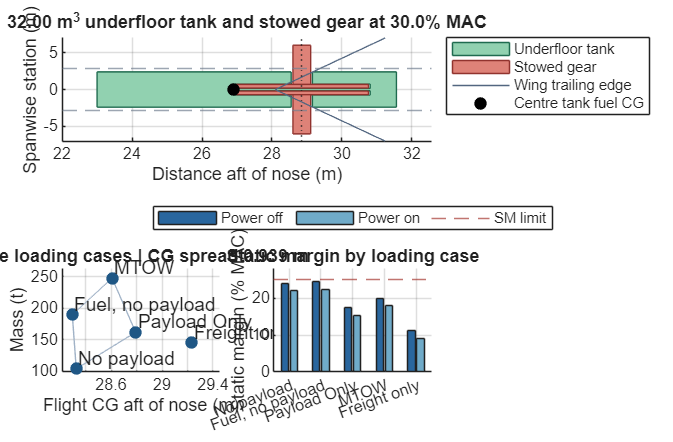


finalPlot = plotFinalDesign(fuelLayout,centreOption,case_names,mCase,xFlight, ...
    smOffAll,smOnAll,100*SM_max,cgSpread_m);
print(finalPlot,fullfile(folder,'final_fuel_cg_stability.png'),'-dpng','-r180');

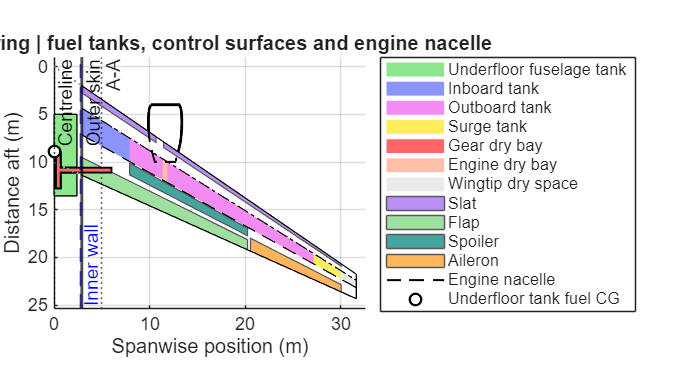

[wingPlot,sectionPlot,underfloorPlot] = plotOriginalWing(fuelLayout,centreOption);
print(wingPlot,fullfile(folder,'wing_top_view.png'),'-dpng','-r200');

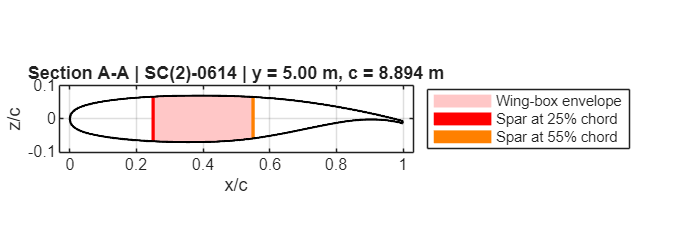

print(sectionPlot,fullfile(folder,'wing_cross_section.png'),'-dpng','-r200');

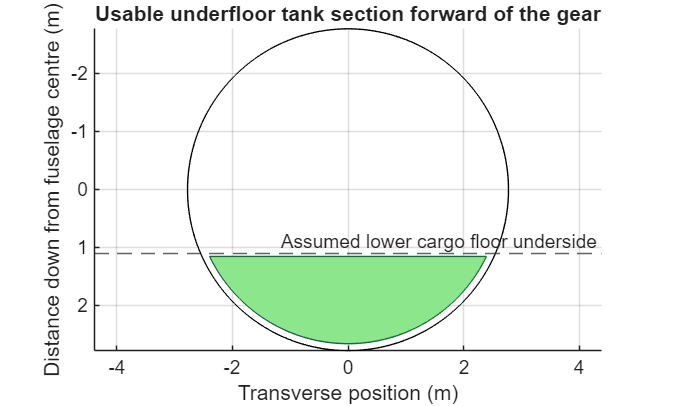

print(underfloorPlot,fullfile(folder,'fuselage_tank_section.png'),'-dpng','-r200');

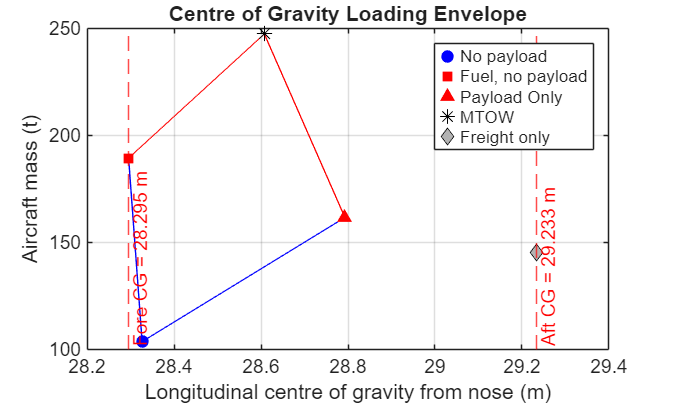

envelopePlot = plotOriginalEnvelope(xFlight,mCase);
print(envelopePlot,fullfile(folder,'cg_loading_envelope_red_blue.png'),'-dpng','-r180');


%% ========================================================================
%  LOCAL FUNCTIONS (must remain at the end of a MATLAB script)
%% ========================================================================

function TW = cruiseTW(WS, alt_ft, beta, alpha, M, CD0, K, ft2m)
    [~, a, ~, rho] = atmosisa(alt_ft*ft2m);
    q  = 0.5*rho*(M*a)^2;
    TW = (alpha/beta)*((q*CD0./(alpha*WS)) + (alpha*WS/q)*K);
end

function TW = climbTW(WS, alt_ft, roc_fpm, V, beta, alpha, CD0, K, ft2m)
    [~, ~, ~, rho] = atmosisa(alt_ft*ft2m);
    q  = 0.5*rho*V^2;
    gamma_term = (roc_fpm*0.00508)/V;      % ROC [m/s] / V
    TW = (alpha/beta)*(gamma_term + (q*CD0./(alpha*WS)) + (alpha*WS/q)*K);
end

function [area, x_ac] = sizeTail(volumeProduct, x_root, x_wing_ac, AR, taper, sweep, exposedFraction)
    % Span is full HT span or fin height. The centroid is measured on one panel.
    rootArm         = x_root - x_wing_ac;
    rootChordFactor = 2/(sqrt(AR)*(1 + taper));
    centroidFactor  = exposedFraction*sqrt(AR)*(1 + 2*taper)/(3*(1 + taper));
    acFactor        = 0.25*rootChordFactor + centroidFactor*tand(sweep);
    area = fzero(@(S) S*(rootArm + acFactor*sqrt(S)) - volumeProduct, ...
                 [0, volumeProduct/rootArm]);
    x_ac = x_root + acFactor*sqrt(area);
end

function [xForward, xAft] = arrangeLD3(holdStart, holdEnd, boxFront, boxAft, pitch, nRows)
    % Longitudinal row centres [m]. Each row holds two LD3s side by side.
    validateattributes(nRows,  {'numeric'}, {'scalar','integer','nonnegative','finite'});
    validateattributes(pitch,  {'numeric'}, {'scalar','positive','finite'});
    assert(all(isfinite([holdStart holdEnd boxFront boxAft])) && ...
        holdEnd > holdStart && boxAft > boxFront, 'Invalid hold or wing-box limits.');
    forwardEnd = min(max(boxFront, holdStart), holdEnd);
    aftStart   = min(max(boxAft,   holdStart), holdEnd);
    tol        = 16*eps(max([1 abs(holdStart) abs(holdEnd)]));
    capForward = floor((forwardEnd - holdStart + tol)/pitch);
    capAft     = floor((holdEnd - aftStart + tol)/pitch);
    if capForward + capAft < nRows
        error('LD3:InsufficientSpace', ...
            '%d lower rows required; only %d forward and %d aft fit.', nRows, capForward, capAft);
    end
    % Fill forward first. Centre the occupied block in each usable bay.
    nf = min(capForward, nRows);
    na = nRows - nf;
    xForward = (holdStart + forwardEnd)/2 + ((1:nf) - (nf+1)/2)*pitch;
    xAft     = (aftStart + holdEnd)/2     + ((1:na) - (na+1)/2)*pitch;
end

function xCG = boundWingFuelCG(x,cellVolume,requiredVolume,direction)
    [x,index] = sort(x,direction);
    cellVolume = cellVolume(index);
    previousVolume = [0; cumsum(cellVolume(1:end-1))];
    usedVolume = min(cellVolume,max(0,requiredVolume-previousVolume));
    xCG = sum(x.*usedVolume)/requiredVolume;
end

function fuelLayout = buildFuelLayout(selectedCapacity,wingArea,wingSpan,taper,quarterSweep,xWingAC)
% Airfoil coordinates from https://m-selig.ae.illinois.edu/ads/coord/sc20614.dat
% Uses the same trapezoidal wing and nose datum as the original CG model.
p.Sref = wingArea;
p.span = wingSpan;
p.taper = taper;
p.quarterChordSweep = quarterSweep;
p.xWingAC_m = xWingAC;
p.rootChord = 2*p.Sref/(p.span*(1+p.taper));
p.tipChord = p.taper*p.rootChord;
p.sweepLE = atand(tand(p.quarterChordSweep) + ...
    (p.rootChord-p.tipChord)/(2*p.span));
p.fuselageWidth = 5.805;          % m, outer diameter at wing box
p.innerDiameter = 5.5507;          % m, inner diameter (plan-view limit)
p.frontSpar = 0.25;               % x/c, ASSUMED as reference image
p.rearSpar = 0.55;                % x/c, ASSUMED as reference image
% Fuselage tank inputs. z is measured down from the fuselage centreline.
p.centreTankOptions_m3 = [28.85 32.00];
p.xTankFront_m = 23.00;          % m aft of nose, below the lower cargo hold
p.xTankAftLimit_m = 36.20;       % m aft of nose, provisional available bay
p.lowerCargoFloorZ_m = 1.10;    % m down, assumed underside of lower cargo floor
p.floorClearance_m = 0.05;
p.skinClearance_m = 0.12;        % radial deduction inside inner fuselage radius
p.tankGearClearance_m = 0.05;    % nominal plan clearance to stowed gear
p.gearStationTargetMAC = 0.30;

p.sparWidth = 0.01;               % chord fraction, illustrative only
p.surgeLength = 0.15*p.span * 0.3;             % m inboard from tip, ASSUMED, not sized
p.tipClearance = 1.6245;              % m, ASSUMED dry space at wingtip  1.6245
% Dimensions numbered in the top-view sketch.
p.headWidth = 0.5;               % m, tyre-section spanwise envelope
p.wingDihedral = 3;              % deg, positive outboard-up
p.rootPivotToAxleHeight = 5.25;    % m, assumed at zero dihedral: 5.5 m bay less half the tyre section
p.gearWingClearance = 0.05;        % m, nominal plan clearance to rear spar and trailing edge
% Provisional ground-model stations, measured aft of nose.
p.xMainContactTarget = 31.10;     % m, effective ground reaction
p.xMainAttachReference = 36.48;   % m, installation reference to verify in CAD
p.gearHeadDepthIn = 150;          % in, overall tyre-section fore-aft envelope
p.gearInboardY = 0.20;            % m, retain the original inboard edge
p.gearRodDiameterIn = 20;        % in, strut outside diameter
p.gearRodDepth = 0.0254*p.gearRodDiameterIn; % m, strut width in stowed plan view
p.gearMaxXC = 1;               % aft limit of rod, local chord fraction
headDepth = 0.0254*p.gearHeadDepthIn;
% Assume a vertical deployed strut and an inboard-stowing strut parallel
% to the dihedral plane. Solve L = H0 + (yAxle + L*cosd(gamma))*tand(gamma).
assert(abs(p.wingDihedral)<90 && p.rootPivotToAxleHeight>0 && p.gearWingClearance>=0);
yAxleStowed = p.gearInboardY+p.headWidth/2;
gearLength = (p.rootPivotToAxleHeight+yAxleStowed*tand(p.wingDihedral))/ ...
    (1-sind(p.wingDihedral));
p.gearEndY = yAxleStowed+gearLength*cosd(p.wingDihedral);
p.gearTotalSpan = p.gearEndY-p.gearInboardY;
p.gearY = [p.gearInboardY p.gearInboardY+p.headWidth p.gearEndY];
assert(p.headWidth>0 && p.headWidth<p.gearTotalSpan && p.gearY(1)>0 && ...
    p.gearEndY<=p.span/2 && headDepth>=p.gearRodDepth && p.gearRodDepth>0 && ...
    p.gearMaxXC>0 && p.gearMaxXC<=1,'Invalid gear dimensions.');
p.engineY = [11.37 11.87];             % m, ASSUMED engine dry bay
p.splitEta = 0.25;
% Plan-view overlays. Eta is measured from the aircraft centreline.
p.slatEta = [0.09 0.3375; 0.3625 0.95]; % one row per slat panel
p.slatXC = [0 0.08];                    % forward 8% of local chord
p.flapEta = [0.09 0.64];
p.flapXC = [0.80 1];                    % aft 20% of local chord
p.spoilerEta = [0.25 0.64];  p.spoilerXC = [0.57 0.72];
p.aileronEta = [0.65 0.95];  p.aileronXC = [0.74 1];
p.nacelleLength = 6.0;          % m, ASSUMED illustrated outer length
p.nacelleDiameter = 3.5;        % m, ASSUMED maximum outer diameter
p.inletAheadLE = 4.0;           % m, ASSUMED at engine centreline
p.sectionY = 5;                  % m, cross-section station !!!!!!!! crossection position random is fine
% Reserve the illustrated surge region and tip clearance from usable volume.
p.volumeFactor = 0.9;           % 80-90 supplied preliminary structure allowance
p.requiredTankVolume = 114.692;   % m^3, previous estimate incl. fuel allowances

%% Embedded SC(2)-0614 coordinates (upper then lower, LE to TE)
coords = [
0.000000 0.000000;
0.002000 0.010800;
0.005000 0.016600;
0.010000 0.022500;
0.020000 0.029800;
0.030000 0.034900;
0.040000 0.038700;
0.050000 0.041800;
0.060000 0.044500;
0.070000 0.046800;
0.080000 0.048900;
0.090000 0.050800;
0.100000 0.052500;
0.110000 0.054100;
0.120000 0.055500;
0.130000 0.056800;
0.140000 0.058000;
0.150000 0.059100;
0.160000 0.060200;
0.170000 0.061200;
0.180000 0.062100;
0.190000 0.062900;
0.200000 0.063700;
0.210000 0.064400;
0.220000 0.065100;
0.230000 0.065700;
0.240000 0.066300;
0.250000 0.066800;
0.260000 0.067300;
0.270000 0.067800;
0.280000 0.068200;
0.290000 0.068600;
0.300000 0.068900;
0.310000 0.069200;
0.320000 0.069400;
0.330000 0.069600;
0.340000 0.069800;
0.350000 0.069900;
0.360000 0.070000;
0.370000 0.070100;
0.380000 0.070100;
0.390000 0.070100;
0.400000 0.070100;
0.410000 0.070000;
0.420000 0.069900;
0.430000 0.069800;
0.440000 0.069600;
0.450000 0.069400;
0.460000 0.069200;
0.470000 0.069000;
0.480000 0.068700;
0.490000 0.068400;
0.500000 0.068100;
0.510000 0.067700;
0.520000 0.067300;
0.530000 0.066900;
0.540000 0.066400;
0.550000 0.065900;
0.560000 0.065300;
0.570000 0.064700;
0.580000 0.064000;
0.590000 0.063300;
0.600000 0.062600;
0.610000 0.061800;
0.620000 0.061000;
0.630000 0.060100;
0.640000 0.059100;
0.650000 0.058100;
0.660000 0.057000;
0.670000 0.055900;
0.680000 0.054700;
0.690000 0.053500;
0.700000 0.052200;
0.710000 0.050900;
0.720000 0.049500;
0.730000 0.048100;
0.740000 0.046600;
0.750000 0.045100;
0.760000 0.043600;
0.770000 0.042000;
0.780000 0.040400;
0.790000 0.038700;
0.800000 0.037000;
0.810000 0.035200;
0.820000 0.033400;
0.830000 0.031600;
0.840000 0.029700;
0.850000 0.027800;
0.860000 0.025800;
0.870000 0.023800;
0.880000 0.021800;
0.890000 0.019700;
0.900000 0.017600;
0.910000 0.015400;
0.920000 0.013200;
0.930000 0.010900;
0.940000 0.008600;
0.950000 0.006200;
0.960000 0.003800;
0.970000 0.001300;
0.980000 -0.001300;
0.990000 -0.003900;
1.000000 -0.006600;
0.000000 0.000000;
0.002000 -0.010800;
0.005000 -0.016600;
0.010000 -0.022500;
0.020000 -0.029800;
0.030000 -0.034900;
0.040000 -0.038800;
0.050000 -0.041900;
0.060000 -0.044600;
0.070000 -0.046900;
0.080000 -0.049000;
0.090000 -0.050900;
0.100000 -0.052600;
0.110000 -0.054200;
0.120000 -0.055700;
0.130000 -0.057000;
0.140000 -0.058200;
0.150000 -0.059400;
0.160000 -0.060500;
0.170000 -0.061500;
0.180000 -0.062400;
0.190000 -0.063300;
0.200000 -0.064100;
0.210000 -0.064800;
0.220000 -0.065500;
0.230000 -0.066100;
0.240000 -0.066700;
0.250000 -0.067200;
0.260000 -0.067700;
0.270000 -0.068100;
0.280000 -0.068500;
0.290000 -0.068800;
0.300000 -0.069100;
0.310000 -0.069300;
0.320000 -0.069500;
0.330000 -0.069700;
0.340000 -0.069800;
0.350000 -0.069900;
0.360000 -0.069900;
0.370000 -0.069800;
0.380000 -0.069700;
0.390000 -0.069600;
0.400000 -0.069400;
0.410000 -0.069200;
0.420000 -0.068900;
0.430000 -0.068600;
0.440000 -0.068200;
0.450000 -0.067700;
0.460000 -0.067200;
0.470000 -0.066600;
0.480000 -0.065900;
0.490000 -0.065100;
0.500000 -0.064200;
0.510000 -0.063200;
0.520000 -0.062200;
0.530000 -0.061100;
0.540000 -0.059900;
0.550000 -0.058600;
0.560000 -0.057200;
0.570000 -0.055700;
0.580000 -0.054100;
0.590000 -0.052500;
0.600000 -0.050800;
0.610000 -0.049100;
0.620000 -0.047300;
0.630000 -0.045500;
0.640000 -0.043600;
0.650000 -0.041700;
0.660000 -0.039700;
0.670000 -0.037700;
0.680000 -0.035600;
0.690000 -0.033600;
0.700000 -0.031500;
0.710000 -0.029400;
0.720000 -0.027400;
0.730000 -0.025300;
0.740000 -0.023300;
0.750000 -0.021300;
0.760000 -0.019300;
0.770000 -0.017400;
0.780000 -0.015500;
0.790000 -0.013700;
0.800000 -0.011900;
0.810000 -0.010200;
0.820000 -0.008600;
0.830000 -0.007200;
0.840000 -0.005900;
0.850000 -0.004700;
0.860000 -0.003700;
0.870000 -0.002900;
0.880000 -0.002300;
0.890000 -0.001900;
0.900000 -0.001700;
0.910000 -0.001700;
0.920000 -0.001900;
0.930000 -0.002400;
0.940000 -0.003100;
0.950000 -0.004100;
0.960000 -0.005400;
0.970000 -0.006900;
0.980000 -0.008700;
0.990000 -0.010800;
1.000000 -0.013200;
];
upper = coords(1:103,:);
lower = coords(104:end,:);
zu = @(x) interp1(upper(:,1),upper(:,2),x,'pchip');
zl = @(x) interp1(lower(:,1),lower(:,2),x,'pchip');
halfSpan = p.span/2;
chord = @(y) p.rootChord+(p.tipChord-p.rootChord).*y/halfSpan;
le = @(y) y*tand(p.sweepLE);
side = p.fuselageWidth/2;
headY = p.gearY(1:2);
rodY = p.gearY(2:3);

% Trapezoidal wing MAC. All x coordinates are aft of the root leading edge.
lambda_w = p.tipChord/p.rootChord;
MAC_w = (2/3)*p.rootChord*(1+lambda_w+lambda_w^2)/(1+lambda_w);
y_MAC_w = (p.span/6)*(1+2*lambda_w)/(1+lambda_w);
x_LEMAC_w = le(y_MAC_w);
xGearPreferred = x_LEMAC_w + p.gearStationTargetMAC*MAC_w;
xRootLENose = p.xWingAC_m-0.25*MAC_w-x_LEMAC_w;

% Fit the straight stowed strut in the exposed wing aft of the rear spar.
% Both boundaries are linear, so extrema occur at the spanwise endpoints.
assert(rodY(2)>side,'The stowed gear attachment must reach the exposed wing.');
stations = [max(side,rodY(1)) rodY(2)];
rearSparLimit = max(le(stations)+(p.rearSpar+p.sparWidth/2)*chord(stations));
aftLimit = min(le(stations)+p.gearMaxXC*chord(stations));
rodAllowance = p.gearRodDepth/2+p.gearWingClearance;
xGearRange = [rearSparLimit+rodAllowance aftLimit-rodAllowance];
assert(xGearRange(1)<=xGearRange(2), ...
    'The stowed strut cannot fit between the rear spar and the aft wing limit.');
xW_main_landing_gear = min(max(xGearPreferred,xGearRange(1)),xGearRange(2));
gearStationMAC = (xW_main_landing_gear-x_LEMAC_w)/MAC_w;
rodX = xW_main_landing_gear+[-0.5 0.5]*p.gearRodDepth;
headX = xW_main_landing_gear+[-0.5 0.5]*headDepth;

%% Size the fuselage tank from the space below the lower cargo floor
bayY = [headY; rodY];
bayX = [headX; rodX];
radius = p.innerDiameter/2-p.skinClearance_m;
tankTop = p.lowerCargoFloorZ_m+p.floorClearance_m;
assert(radius>tankTop && tankTop>=0 && p.xTankAftLimit_m>p.xTankFront_m ...
    && p.tankGearClearance_m>=0,'Invalid fuselage tank envelope.');
tankHalfWidth = sqrt(radius^2-tankTop^2);
clearance = [-1 1]*p.tankGearClearance_m;
keepoutY = max(0,bayY+clearance);
keepoutX = xRootLENose+bayX+clearance;
tankEnvelope = @(aft) fuselageTankProperties(p.xTankFront_m,aft, ...
    tankHalfWidth,radius,tankTop,keepoutX,keepoutY,p.volumeFactor);

centreOptions = struct('capacity_m3',{},'xCG_m',{},'zCG_m',{},'xAft_m',{});
availableCentreVolume = tankEnvelope(p.xTankAftLimit_m);
for k = 1:numel(p.centreTankOptions_m3)
    capacity = p.centreTankOptions_m3(k);
    if capacity>availableCentreVolume
        fprintf('Centre option %.2f m^3 exceeds available underfloor volume %.2f m^3.\n', ...
            capacity,availableCentreVolume);
        continue;
    end
    xAft = fzero(@(x) tankEnvelope(x)-capacity,[p.xTankFront_m p.xTankAftLimit_m]);
    [volume,xCG,zCG] = fuselageTankProperties(p.xTankFront_m,xAft, ...
        tankHalfWidth,radius,tankTop,keepoutX,keepoutY,p.volumeFactor);
    assert(abs(volume-capacity)<1e-6,'Centre fuel volume failed to close.');
    centreOptions(end+1) = struct('capacity_m3',capacity,'xCG_m',xCG, ...
        'zCG_m',zCG,'xAft_m',xAft);
end
assert(any(abs([centreOptions.capacity_m3]-selectedCapacity)<1e-8), ...
    'Selected centre tank capacity does not fit the underfloor envelope.');

% Discretise both semiwings over the wet wing-box regions only.
wetLimit = halfSpan-p.tipClearance-p.surgeLength;
assert(wetLimit>side && p.frontSpar>0 && p.rearSpar<1 && p.frontSpar<p.rearSpar);
edges = unique([side wetLimit max(side,min(wetLimit,[p.gearY p.engineY]))]);
wingCellX_m = [];
wingCellVolume_m3 = [];
for i = 1:numel(edges)-1
    y = edges(i:i+1);
    mid = mean(y);
    if mid>=p.engineY(1) && mid<p.engineY(2)
        continue;
    end
    nY = max(2,ceil(diff(y)/0.05));
    nQ = max(2,ceil((p.rearSpar-p.frontSpar)/0.005));
    dy = diff(y)/nY;
    dq = (p.rearSpar-p.frontSpar)/nQ;
    [Y,Q] = ndgrid(y(1)+((1:nY)-0.5)*dy,p.frontSpar+((1:nQ)-0.5)*dq);
    X = le(Y)+Q.*chord(Y);
    gearBay = find(mid>=bayY(:,1) & mid<bayY(:,2),1);
    usable = true(size(X));
    if ~isempty(gearBay)
        usable = X<bayX(gearBay,1) | X>bayX(gearBay,2);
    end
    cellVolume = 2*p.volumeFactor*dy*dq*chord(Y).^2.*(zu(Q)-zl(Q));
    wingCellX_m = [wingCellX_m; xRootLENose+reshape(X(usable),[],1)];
    wingCellVolume_m3 = [wingCellVolume_m3; reshape(cellVolume(usable),[],1)];
end
gearNoseX = xRootLENose+xW_main_landing_gear;
plan = struct('tankFront_m',p.xTankFront_m,'tankHalfWidth_m',tankHalfWidth, ...
    'gearX_m',xRootLENose+bayX,'gearY_m',bayY,'keepoutX_m',keepoutX, ...
    'keepoutY_m',keepoutY,'noseRootLE_m',xRootLENose,'fuselageHalfWidth_m',side, ...
    'gearStation_m',gearNoseX,'leadingEdgeSlope',tand(p.sweepLE), ...
    'rootChord_m',p.rootChord,'tipChord_m',p.tipChord,'halfSpan_m',halfSpan, ...
    'tankTopZ_m',tankTop,'radius_m',radius,'surgeStart_m',wetLimit, ...
    'inboardEnd_m',p.splitEta*halfSpan,'airfoilUpper',upper,'airfoilLower',lower, ...
    'wingSettings',p);
fuelLayout = struct('centreOptions',centreOptions,'wingCellX_m',wingCellX_m, ...
    'wingCellVolume_m3',wingCellVolume_m3,'gearStationMAC',gearStationMAC, ...
    'gearLength_m',gearLength,'plan',plan);
for k = 1:numel(centreOptions)
    option = centreOptions(k);
    totalCapacity = option.capacity_m3+sum(wingCellVolume_m3);
    fprintf('Centre %.2f m^3: x %.3f to %.3f m; xCG %.3f m from nose.\n', ...
        option.capacity_m3,p.xTankFront_m,option.xAft_m,option.xCG_m);
    fprintf('Total %.3f m^3 excluding surge; margin to %.3f m^3 legacy target %+.3f m^3.\n', ...
        totalCapacity,p.requiredTankVolume,totalCapacity-p.requiredTankVolume);
end
fprintf('Stowed gear %.2f%% MAC at %.3f m from nose; tank top %.2f m below fuselage centre.\n', ...
    100*gearStationMAC,gearNoseX,tankTop);
fprintf('Check lower cargo floor, wing carry-through and gear retraction sweep in CAD.\n');
end

function [volume,xCG,zCG] = fuselageTankProperties(front,aft,halfWidth,radius,top,gearX,gearY,factor)
    % Partition the usable half-section into spanwise and longitudinal strips.
    % Overlapping keep-outs are treated as a union at each strip midpoint.
    yEdges = unique([0 halfWidth min(halfWidth,gearY(:).')]);
    xEdges = unique([front aft max(front,min(aft,gearX(:).'))]);
    shell = @(y) sqrt(max(0,radius^2-y.^2));
    volume = 0;
    momentX = 0;
    momentZ = 0;
    for i = 1:numel(yEdges)-1
        y = yEdges(i:i+1);
        ym = mean(y);
        belt = 2*factor*integral(@(t) shell(t)-top,y(1),y(2));
        beltZ = factor*integral(@(t) shell(t).^2-top^2,y(1),y(2));
        active = gearY(:,1)<ym & ym<gearY(:,2);
        for j = 1:numel(xEdges)-1
            x = xEdges(j:j+1);
            xm = mean(x);
            if any(active & gearX(:,1)<xm & xm<gearX(:,2))
                continue;
            end
            dv = belt*diff(x);
            volume = volume+dv;
            momentX = momentX+dv*xm;
            momentZ = momentZ+beltZ*diff(x);
        end
    end
    xCG = momentX/volume;
    zCG = momentZ/volume;
end

function f = plotFinalDesign(layout,option,cases,mass,xCG,smOff,smOn,smLimit,cgSpread)
    f = figure('Color','w','Name','Underfloor fuel and longitudinal stability', ...
        'Position',[100 100 1240 820]);
    panel = tiledlayout(f,2,2,'TileSpacing','compact','Padding','compact');
    plan = layout.plan;
    ax = nexttile(panel,[1 2]);
    hold(ax,'on');
    tankX = [plan.tankFront_m option.xAft_m];
    tankY = [-1 1]*plan.tankHalfWidth_m;
    tank = rectanglePolygon(tankX,tankY);
    for side = [-1 1]
        for i = 1:size(plan.keepoutX_m,1)
            tank = subtract(tank,rectanglePolygon(plan.keepoutX_m(i,:),side*plan.keepoutY_m(i,:)));
        end
    end
    tankPlot = plot(ax,tank,'FaceColor',[.57 .82 .69],'FaceAlpha',1,'EdgeColor',[.12 .42 .31]);
    for side = [-1 1]
        for i = 1:size(plan.gearX_m,1)
            gearPlot = plot(ax,rectanglePolygon(plan.gearX_m(i,:),side*plan.gearY_m(i,:)), ...
                'FaceColor',[.87 .51 .47],'FaceAlpha',1,'EdgeColor',[.57 .20 .18]);
        end
    end
    y = linspace(0,7,100);
    te = plan.noseRootLE_m+plan.leadingEdgeSlope*y+plan.rootChord_m ...
        +(plan.tipChord_m-plan.rootChord_m)*y/plan.halfSpan_m;
    tePlot = plot(ax,te,y,'Color',[.32 .40 .50]);
    plot(ax,te,-y,'Color',[.32 .40 .50],'HandleVisibility','off');
    for side = [-1 1]
        yline(ax,side*plan.fuselageHalfWidth_m,'--','Color',[.45 .50 .57],'HandleVisibility','off');
    end
    cgPlot = plot(ax,option.xCG_m,0,'ko','MarkerFaceColor','k');
    xline(ax,plan.gearStation_m,':','HandleVisibility','off');
    xlim(ax,[tankX(1)-1 max([tankX(2),plan.gearX_m(:).',max(te)])+1]);
    ylim(ax,[-7 7]);
    grid(ax,'on');
    xlabel(ax,'Distance aft of nose (m)');
    ylabel(ax,'Spanwise station (m)');
    title(ax,sprintf('%.2f m^3 underfloor tank and stowed gear at %.1f%% MAC', ...
        option.capacity_m3,100*layout.gearStationMAC));
    legend(ax,[tankPlot gearPlot tePlot cgPlot], ...
        {'Underfloor tank','Stowed gear','Wing trailing edge','Centre tank fuel CG'}, ...
        'Location','northeastoutside');

    ax = nexttile(panel);
    hold(ax,'on'); grid(ax,'on');
    connections = [1 2; 1 3; 3 4; 2 4];
    for i = 1:size(connections,1)
        edge = connections(i,:);
        plot(ax,xCG(edge),mass(edge)/1000,'-','Color',[.63 .70 .78]);
    end
    scatter(ax,xCG,mass/1000,42,[.12 .34 .52],'filled');
    for i = 1:numel(cases)
        text(ax,xCG(i)+0.015,mass(i)/1000,cases{i},'VerticalAlignment','bottom');
    end
    xlim(ax,[min(xCG)-.08 max(xCG)+.22]);
    ylim(ax,[min(mass)/1000-5 max(mass)/1000+15]);
    xlabel(ax,'Flight CG aft of nose (m)'); ylabel(ax,'Mass (t)');
    title(ax,sprintf('Five loading cases | CG spread %.3f m',cgSpread));

    ax = nexttile(panel);
    hold(ax,'on'); grid(ax,'on');
    bars = bar(ax,[smOff smOn]);
    bars(1).FaceColor = [.16 .40 .62];
    bars(2).FaceColor = [.44 .67 .79];
    h = yline(ax,smLimit,'--','Color',[.65 .23 .20]);
    xticks(ax,1:numel(cases)); xticklabels(ax,cases); xtickangle(ax,20);
    ylim(ax,[min(0,min(smOn)-2) max(smLimit+3,max(smOff)+3)]);
    ylabel(ax,'Static margin (% MAC)');
    title(ax,'Static margin by loading case');
    legend(ax,[bars(1) bars(2) h],{'Power off','Power on','SM limit'},'Location','northoutside', ...
        'Orientation','horizontal');
end

function rectangle = rectanglePolygon(x,y)
    rectangle = polyshape(x([1 2 2 1]),y([1 1 2 2]));
end

function f = plotOriginalEnvelope(xc,mass)
    % Plot (tonnes)
    f = figure('Name','Centre of Gravity Loading Envelope','Color','white');
    hold on; grid on; box on;
    tons = mass/1e3;
    plot(xc([1 3]), tons([1 3]), 'b-', 'HandleVisibility','off');
    plot(xc([1 2]), tons([1 2]), 'b-', 'HandleVisibility','off');
    plot(xc([3 4]), tons([3 4]), 'r-', 'HandleVisibility','off');
    plot(xc([2 4]), tons([2 4]), 'r-', 'HandleVisibility','off');
    h = gobjects(1,5);
    h(1) = plot(xc(1), tons(1), 'bo', 'MarkerFaceColor','b');
    h(2) = plot(xc(2), tons(2), 'rs', 'MarkerFaceColor','r');
    h(3) = plot(xc(3), tons(3), 'r^', 'MarkerFaceColor','r');
    h(4) = plot(xc(4), tons(4), 'k*', 'MarkerSize',8);
    h(5) = plot(xc(5), tons(5), 'kd', 'MarkerFaceColor',[.7 .7 .7]);
    xline(min(xc),'--r',sprintf('Fore CG = %.3f m',min(xc)),'LabelVerticalAlignment','bottom');
    xline(max(xc),'--r',sprintf('Aft CG = %.3f m',max(xc)),'LabelVerticalAlignment','bottom');
    legend(h, {'No payload','Fuel, no payload','Payload Only','MTOW','Freight only'}, 'Location','northeast');
    xlabel('Longitudinal centre of gravity from nose (m)');
    ylabel('Aircraft mass (t)');
    title('Centre of Gravity Loading Envelope');
    hold off;
end

function [f1,f2,f3] = plotOriginalWing(layout,option)
plan = layout.plan;
p = plan.wingSettings;
halfSpan = plan.halfSpan_m;
chord = @(y) plan.rootChord_m+(plan.tipChord_m-plan.rootChord_m).*y/halfSpan;
le = @(y) plan.leadingEdgeSlope*y;
headY = plan.gearY_m(1,:);
rodY = plan.gearY_m(2,:);
headX = plan.gearX_m(1,:)-plan.noseRootLE_m;
rodX = plan.gearX_m(2,:)-plan.noseRootLE_m;
centreTankCGX = option.xCG_m-plan.noseRootLE_m;
names = {'Underfloor fuselage tank','Inboard tank','Outboard tank','Surge tank', ...
    'Gear dry bay','Engine dry bay','Wingtip dry space'};
colors = [.55 .90 .55;.55 .58 1;.95 .55 .95;1 .93 .35;1 .40 .40;1 .75 .65;.92 .92 .92];
f1 = figure('Color','w','Name','Full right-wing plan','Position',[100 100 1240 700]);
hold on;
handles = gobjects(1,numel(names));
for k = 1:numel(names)
    handles(k) = fill(NaN,NaN,colors(k,:),'EdgeColor','none');
end
centrePlan = rectanglePolygon([0 plan.tankHalfWidth_m], ...
    [plan.tankFront_m option.xAft_m]-plan.noseRootLE_m);
for k = 1:size(plan.keepoutX_m,1)
    centrePlan = subtract(centrePlan,rectanglePolygon(plan.keepoutY_m(k,:), ...
        plan.keepoutX_m(k,:)-plan.noseRootLE_m));
end
plot(centrePlan,'FaceColor',colors(1,:),'FaceAlpha',1,'EdgeColor','k');
outerTipClearance = halfSpan-p.tipClearance;
edges = unique([p.fuselageWidth/2 plan.inboardEnd_m p.engineY p.gearY(3) ...
    plan.surgeStart_m outerTipClearance halfSpan]);
edges = edges(edges>=p.fuselageWidth/2 & edges<=halfSpan);
for i = 1:numel(edges)-1
    y = edges(i:i+1);
    mid = mean(y);
    q = [p.frontSpar p.rearSpar];
    if mid>=p.engineY(1) && mid<p.engineY(2)
        k = 6;
    elseif mid<plan.inboardEnd_m
        k = 2;
    elseif mid<plan.surgeStart_m
        k = 3;
    elseif mid<outerTipClearance
        k = 4;
    else
        k = 7;
    end
    yf = [y fliplr(y)];
    xf = [le(y)+q(1)*chord(y) fliplr(le(y)+q(2)*chord(y))];
    tankPanel = polyshape(yf,xf);
    if mid<rodY(2) && mid>=rodY(1) && any(k==[2 3])
        tankPanel = subtract(tankPanel,rectanglePolygon(rodY,rodX));
    end
    plot(tankPanel,'FaceColor',colors(k,:),'FaceAlpha',1,'EdgeColor','none');
end
% Right-hand gear bay outline.
gy = [headY rodY(1) rodY(2) rodY(2) rodY(1) headY(2) headY(1)];
gx = [headX(1) headX(1) rodX(1) rodX(1) rodX(2) rodX(2) headX(2) headX(2)];
% Stowed control surfaces, following the local chord at each span station.
surfaceNames = {'Slat','Flap','Spoiler','Aileron'};
surfaceColors = [.72 .56 .96; .62 .88 .62; .26 .65 .62; 1 .71 .36];
surfaceY = {p.slatEta*halfSpan, p.flapEta*halfSpan, ...
            p.spoilerEta*halfSpan, p.aileronEta*halfSpan};
surfaceXC = {p.slatXC,p.flapXC,p.spoilerXC,p.aileronXC};
surfaceHandles = gobjects(1,4);
for k = 1:4
    surfaceHandles(k) = fill(NaN,NaN,surfaceColors(k,:),'EdgeColor',[.35 .35 .35]);
    for interval = 1:size(surfaceY{k},1)
        y = surfaceY{k}(interval,:);
        if y(2)<=y(1), continue; end
        q = surfaceXC{k};
        fill([y fliplr(y)], [le(y)+q(1)*chord(y) fliplr(le(y)+q(2)*chord(y))], ...
            surfaceColors(k,:),'EdgeColor',[.35 .35 .35],'LineWidth',0.65);
    end
end

fill(gy,gx,colors(5,:),'EdgeColor','k','LineWidth',1);

% Projected underwing nacelle. Draw the portion beneath the wing dashed.
engineY = mean(p.engineY);
inletX = le(engineY)-p.inletAheadLE;
t = linspace(0,1,151);
radius = 0.5*p.nacelleDiameter*interp1([0 .09 .32 .60 .82 1], ...
    [.84 .96 1 .94 .78 .61],t,'pchip');
outlineY = engineY + [-radius fliplr(radius) -radius(1)];
outlineX = inletX + p.nacelleLength*[t fliplr(t) t(1)];
hidden = outlineX>=le(outlineY) & outlineX<=le(outlineY)+chord(outlineY);
nacelleHandle = plot(outlineY,outlineX,'k--','LineWidth',1.1);
visibleX = outlineX;
visibleX(hidden) = NaN;
plot(outlineY,visibleX,'k-','LineWidth',1.5);
% Exposed wing outline is solid; buried wing outline is dotted grey.
y=[p.fuselageWidth/2 halfSpan];
plot([y fliplr(y)],[le(y) fliplr(le(y)+chord(y))],'k-');
y=[0 p.fuselageWidth/2];
plot(y,le(y),':','Color',[.6 .6 .6],'LineWidth',1.2);
plot(y,le(y)+chord(y),':','Color',[.6 .6 .6],'LineWidth',1.2);
y=[p.fuselageWidth/2 halfSpan];
plot(y,le(y)+p.frontSpar*chord(y),'k-.',y,le(y)+p.rearSpar*chord(y),'k--');
xline(0,'k:','Centreline');
centreCGHandle = plot(0,centreTankCGX,'ko','MarkerFaceColor','w', ...
    'LineWidth',1.2,'Clipping','off');
xline(p.innerDiameter/2,'b--','Inner wall','LabelVerticalAlignment','bottom','LineWidth',1);
xline(p.fuselageWidth/2,'k-','Outer skin','LabelVerticalAlignment','top','LineWidth',1.5);
xline(p.sectionY,':','A-A'); axis equal; grid on; set(gca,'YDir','reverse');
xlim([0 halfSpan+1]);
ylim([min([-1 headX(1)-1 inletX-1]) max(le(halfSpan)+chord(halfSpan)+1,headX(2)+1)]);
xlabel('Spanwise position (m)'); ylabel('Distance aft (m)');
title('Right wing | fuel tanks, control surfaces and engine nacelle');
legend([handles surfaceHandles nacelleHandle centreCGHandle], ...
    [names surfaceNames {'Engine nacelle','Underfloor tank fuel CG'}], ...
    'Location','eastoutside');

upper = plan.airfoilUpper;
lower = plan.airfoilLower;
zu = @(x) interp1(upper(:,1),upper(:,2),x,'pchip');
zl = @(x) interp1(lower(:,1),lower(:,2),x,'pchip');
%% Cross-section at selected span station
f2 = figure('Color','w','Position',[100 180 1200 440]); hold on;
x = linspace(0,1,1000);
sectionBounds = [p.frontSpar p.rearSpar];
xb = linspace(sectionBounds(1),sectionBounds(2),400);
fill([xb fliplr(xb)],[zu(xb) fliplr(zl(xb))],[1 .78 .78], ...
    'EdgeColor','none','DisplayName','Wing-box envelope');
sparLocations = sectionBounds;
colors = [1 0 0;1 .5 0];
for k=1:numel(sparLocations)
    xx = linspace(sparLocations(k)-p.sparWidth/2, ...
        sparLocations(k)+p.sparWidth/2,30);
    fill([xx fliplr(xx)],[zu(xx) fliplr(zl(xx))],colors(k,:), ...
        'EdgeColor','none','DisplayName',sprintf('Spar at %.0f%% chord',100*sparLocations(k)));
end
plot(x,zu(x),'k',x,zl(x),'k','LineWidth',1.2,'HandleVisibility','off');
plot([1 1],[zl(1) zu(1)],'k','HandleVisibility','off');
axis equal; xlim([-.03 1.03]); ylim([-.10 .10]); grid on; box on;
xlabel('x/c'); ylabel('z/c');
sectionChord = chord(p.sectionY);
title(sprintf('Section A-A | SC(2)-0614 | y = %.2f m, c = %.3f m', ...
    p.sectionY,sectionChord));
legend('Location','eastoutside');


tankHalfWidth = plan.tankHalfWidth_m;
radius = plan.radius_m;
tankTop = plan.tankTopZ_m;
f3 = figure('Color','w','Name','Fuselage underfloor tank section'); hold on;
angle = linspace(0,2*pi,401);
plot(p.innerDiameter/2*cos(angle),p.innerDiameter/2*sin(angle),'k-');
sectionY = linspace(-tankHalfWidth,tankHalfWidth,401);
sectionBottom = sqrt(max(0,radius^2-sectionY.^2));
fill([sectionY fliplr(sectionY)], ...
    [tankTop+zeros(size(sectionY)) fliplr(sectionBottom)], ...
    [.55 .90 .55],'EdgeColor',[.1 .4 .25]);
yline(p.lowerCargoFloorZ_m,'--','Assumed lower cargo floor underside');
axis equal; grid on; set(gca,'YDir','reverse');
xlabel('Transverse position (m)'); ylabel('Distance down from fuselage centre (m)');
title('Usable underfloor tank section forward of the gear');


end
